## Classification of the Antarctic sea ice cover

% Setup
clear all
clc
close all
addpath functions
addpath /Users/noahday/GitHub/CICE-analyser/processing

historydir = '/Volumes/NoahDay5TB/WIMonAlessandroRun/history/2019/';%'/Users/noahday/Maths1/access-forcing-2010-fixed-ic/history/2019/';

a = dir([historydir '/*.nc']);
n_files = numel(a);

for i = 1:n_files
   filenames(i,:) = strcat(historydir,a(i).name);
   dirdates(i,:) = a(i).name(6:end-3);
end
pca_filenames = filenames(:,:);
pca_dates = dirdates(:,:);

%% PCA for CICE data
% Columns are data
sector = "SH"; %"vichi2";
close all
% large = sheet ice
pca_filenames = filenames(1:end,:);
pca_dates = dirdates(1:end,:);
var_list = {'aice','hi','iage','pancake','large','fsdrad','frazil','frzmlt','congel','sice','strint','dafsd_latg','dafsd_latm','dafsd_newi','dafsd_weld','dafsd_wave','full_fsd'};
[X_temp, row_idx]= read_data_vec(pca_filenames,sector,var_list); % [var_list, lon, lat]
[~, ~,dep] = size(X_temp);

%clear X_temp
label_vec = variable_dict(var_list);
size(X_temp)

ans =        29880          30         365


%% Clean the data
clc
clear X_new

for i = 1:dep
    % Step 0: removing NaN
    idx1 = isnan(X_temp(:,:,i));
    idx = logical(idx1);
    [len, wid] = size(X_temp(:,:,i));
    
    wid = wid - 2;
    count = 1;
    for j = 1:len
        if sum(idx(j,:)) == 0
            X_new(count,:,i) = X_temp(j,:,i);
            count  = count + 1;
        end
    end
    X_new_unstandard = X_new;
    %clear X_new_unstandard
    [row_idx(i),~] = size(X_new(:,:,i));
end

disp('X_new done')

X_new done



X_temp = [];
for i = 1:dep
    X_temp = [X_temp; X_new(:,:,i)];
end
X_new = X_temp;


for j = 1:wid
    if min(X_new(:,j)) < 0
        % If negatives, then recentre so its all positive
        max_X(j) = max(X_new(:,j));
        min_X(j) = min(X_new(:,j));
        X_new(:,j) = (X_new(:,j) - min_X(j))/(max_X(j) - min_X(j));
    end
    %Step 1: Log transformation as almost all of the data is highly skewed
    X_new(:,j) = log(X_new(:,j)+1);
    %Step 2: Standardization
    % Calculate mean
    mean_X(j) = mean(X_new(:,j));
     % Calculate standard deviation
    std_X(j) = std(X_new(:,j));
    
    X_new(:,j) = X_new(:,j)/std_X(j);

    % Standardise the data
    
   max_X(j) = max(X_new(:,j));
   min_X(j) = min(X_new(:,j));
   X_new(:,j) = (X_new(:,j) - min_X(j))/(max_X(j) - min_X(j));
end
clear X_temp

## Checking the standardisation

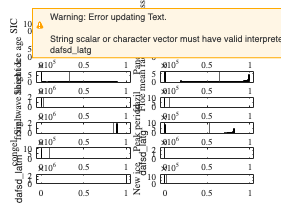

[len, wid] = size(X_new);
len = 14;
close
figure
for i = 1:len
    subplot(len/2,2,i)
%     if i == 1
%         histogram(log(X_new(:,i)+1))
%         ylabel(label_vec{i})
%     else
        histogram(X_new(:,i))
        ylabel(label_vec{i})
%     end
    xline(mean(X_new(:,i)))
end

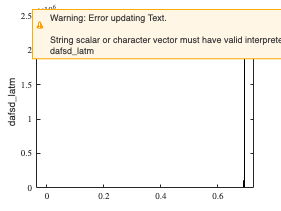


% figure
% for i = 1:len
%     subplot(len,1,i)
%     histogram(X_new(:,i)./std(X_new(:,i)))
% end
i = 13;
figure
histogram(log(X_new(:,i)+1))
ylabel(label_vec{i})

#### PRINCIPAL COMPONENT ANALYSIS 

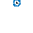

% Step 2: Covariance analysis  
X_cov = X_new(:,1:wid);
% C = cov(X_cov);
% close all
% figure;
% R = corrplot(double(X_cov),'varNames',label_vec);

% conFigure(11,1)
% [~, h_corrmat, h_colorbar] = plot_corrmat([],... % leave timeSeries input empty, since already calculated corrmat
%    'corrmat', R,... % the correlation matrix
%    'title', 'Ice conditions',... % plot title
%    'labels', {'aice','pan prev.','thickness','iage','fsdrad'},... % correlation matrix cell labels
%    'label_FontSize', 11,... % long labels get cutoff with larger fonts
%    'outline', 1); % outline the cells (appearance improvement)

%% plotting cluster analysis

f = figure;
[coeff,score,latent,tsquared,explained] = pca(X_cov);
% The rows of coeff contain the coefficients for the five ice variables, and its columns correspond to five principal components.
% Each column of score corresponds to one principal component. 
% The vector, latent, stores the variances of the five principal components.

% Reconstruct the centered ingredients data.
% Xcentered = score*coeff';

scatter(score(:,1),score(:,2),'o')
axis equal
xlabel('1st Principal Component')
ylabel('2nd Principal Component')

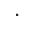



f = figure;
bar(1:numel(explained),explained)
ylabel('$\%$ of variance explained','Interpreter','latex')
xlabel("Principal components",'Interpreter','latex')

%exportgraphics(f,'percentageofvariance.pdf','ContentType','vector')
fprintf('%g percent of the variance is explained by the first two principal components', sum(explained(1:2)))

56.1974 percent of the variance is explained by the first two principal components

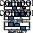

% 
% figure
% for i = 1:numel(explained)
%    subplot(3,1,i)
%    hist(score(:,i))%,'varlabels',{'aice','pancake prev.','thickness','age','fsdrad','SWH'});
% end

%close all
f = figure;
for i = 1:3
 subplot(3,1,i)
 temp = coeff(:,i);
 idx = abs(temp) > 1/sqrt(length(temp));
 loadings = temp(idx);
 loadings_label = label_vec(idx);
 bar(loadings)
 xticks(1:length(loadings))
 set(gca, 'XTickLabel',loadings_label)
 title(sprintf('PCA component %g',i))
 ylabel('Loadings')
end

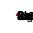

conFigure(11)
f = figure;
biplot(coeff(:,1:2),'scores',score(:,1:2),'varlabels',label_vec(1:length(coeff))); 

#### DETERMINING THE NUMBER OF CLUSTERS

%% Clustering
%X = score(:,1:2);
close all
%rng(1); % For reproducibility
num_clusters = 10;
totSum = zeros(num_clusters,1);
for i = 1:num_clusters
    [~,~,SUMD] = kmeans(X_new(:,1:end-2),i,'MaxIter',300);
    totSum(i) = SUMD(1);
end

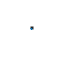


conFigure(11)
plot(totSum)
ylabel 'Total within sum of squares'
xlabel 'Number of clusters {k}'

%X = score(:,1:2);
eva = evalclusters(X_new(:,1:end-2),'kmeans','silhouette','KList',1:10)
plot(eva)


eva = evalclusters(X_new(:,1:end-2),'kmeans','CalinskiHarabasz','KList',1:6)

eva =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 3206890
         InspectedK: [1 2 3 4 5 6]
    CriterionValues: [NaN 5.6231e+06 4.8990e+06 4.9723e+06 4.4496e+06 4.1744e+06]
           OptimalK: 2


temp = eva.CriterionValues;
%eva.CriterionValues = mean(temp);

f = figure

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  Show all properties


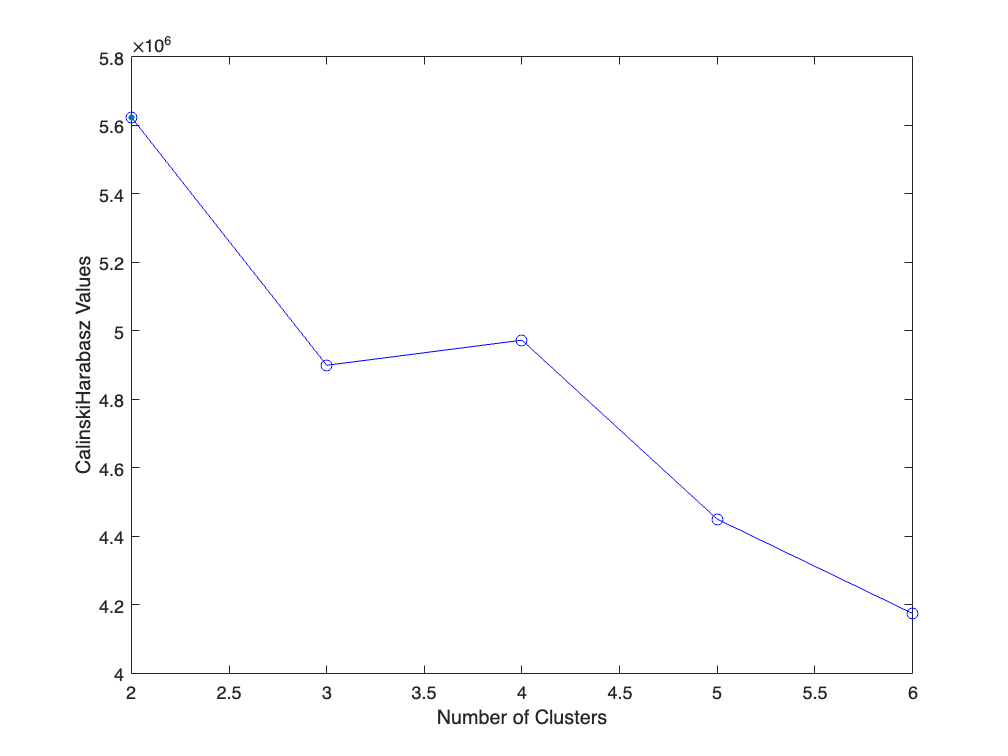

plot(eva)

%exportgraphics(f,'CalinskiTest.pdf','ContentType','vector')


#### KMEANS CLUSTERING

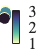

%X = score(:,1:2);
X = X_new(:,1:end-2);
num_clusters = 3;
[idx,C] = kmeans(X,num_clusters,'MaxIter',300);
kmeans_cluster.idx = idx;
kmeans_cluster.row_idx = row_idx;
kmeans_cluster.label_vec = label_vec;
kmeans_cluster.C = C;
kmeans_cluster.X_new = X_new;
kmeans_cluster.X_new_unstandard = X_new;
kmeans_cluster.num_clusters = num_clusters;
save_filename = strcat('kmeans_jan_dec_2019_',sprintf('%g',num_clusters),'_classes.mat');
save(save_filename,'kmeans_cluster');
% x1 = linspace(min(X(:,1)),max(X(:,1)),1000);%min(X(:,1)):0.5:max(X(:,1));
% x2 = linspace(min(X(:,2)),max(X(:,2)),1000);%min(X(:,2)):0.5:max(X(:,2));
% [x1G,x2G] = meshgrid(x1,x2);
% XGrid = [x1G(:),x2G(:)]; % Defines a fine grid on the plot
% 
% idx2Region = kmeans(XGrid,num_clusters,'MaxIter',200,'Start','cluster');

% conFigure(12,1)
% figure;
% subplot(1,1,1);
% gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
%     [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
% hold on;
% plot(X(:,1),X(:,2),'k*','MarkerSize',5);
% hold off
% %plotv(coeff(:,1:2))
% %xlabel 'Pancake prevalance [$\%$]'; 
% set(gca,'xticklabel',{[]})
% ylabel 'PCA2';
% xlabel 'PCA1';
% legend off
% %legend('Region 1','Region 2','Region 3','Data','Location','NorthEast');
% 
% hold off;
% New clustering model?

% Plot scatter with dots matching the colour of each region!
f = figure;
scatter(X(:,1),X(:,2),[],idx,'filled');
set(gca,'xticklabel',{[]})
ylabel 'PCA2';
xlabel 'PCA1';
colorbar
cmocean('deep')

legend off
%exportgraphics(f,'cluster.pdf','ContentType','vector')


## Plot worldmap 

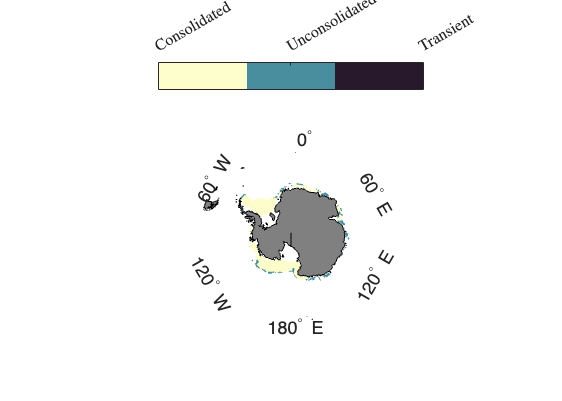

% Classes
addpath functions
% load('kmeans_may_sep_2019_4_classes.mat');
%load(save_filename);
% idx = kmeans_cluster.idx;
% row_idx = kmeans_cluster.row_idx;
% label_vec = kmeans_cluster.label_vec;
% C = kmeans_cluster.C;
% X_new = kmeans_cluster.X_new;
% num_clusters = size(C,1);


[lat,lon,~,ulat,ulon] = grid_read('om2');
sector  =  "SH";
clear X_map kmeans_cluster
% Make worldmap with colour matching
[len,wid] = size(lat);
file_number = 80; % Days

index_lat = X_new(:,end-1) == X_new(10,end-1);
index_lon = X_new(:,end) == X_new(10,end);
index_both = index_lat.*index_lon;

row_file = find(index_both);%[0,cumsum(row_idx)];
row_vec = row_file(file_number)+1:row_file(file_number+1);
file_idx = idx(row_vec);
X_map = [file_idx, X_new(row_vec,end-1:end)];%[file_idx, X_new(:,end-1:end)];%
k_means = NaN.*ones(len,wid);
for i = 1:length(file_idx)
    [lon_pos,lat_pos,~] = near2(lon,lat,X_map(i,3),X_map(i,2));
    k_means(lon_pos,lat_pos) = file_idx(i); 
end
aice = data_format_sector(pca_filenames(file_number,:),'aice',sector);
ice_mask =  aice > 0.15;
k_means(~ice_mask) = NaN;

region_label = {'Consolidated','Unconsolidated','Transient'};
close
conFigure(11)
f = figure;
w = worldmap('World');
    axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-50]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off') 
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -35);
    setm(w, 'grid', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,k_means)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.5 0.5])
    cb = colorbar;
    cmocean('deep',num_clusters)
    cb.TickLabels = region_label;
    cb.Ticks = 1:num_clusters;
    cb.Location = 'northoutside';
    caxis([1,num_clusters])
    %legend(region_label)
    %hold off
exportgraphics(f,sprintf('worldmap_%g.png',file_number),'ContentType','image','Resolution',300)

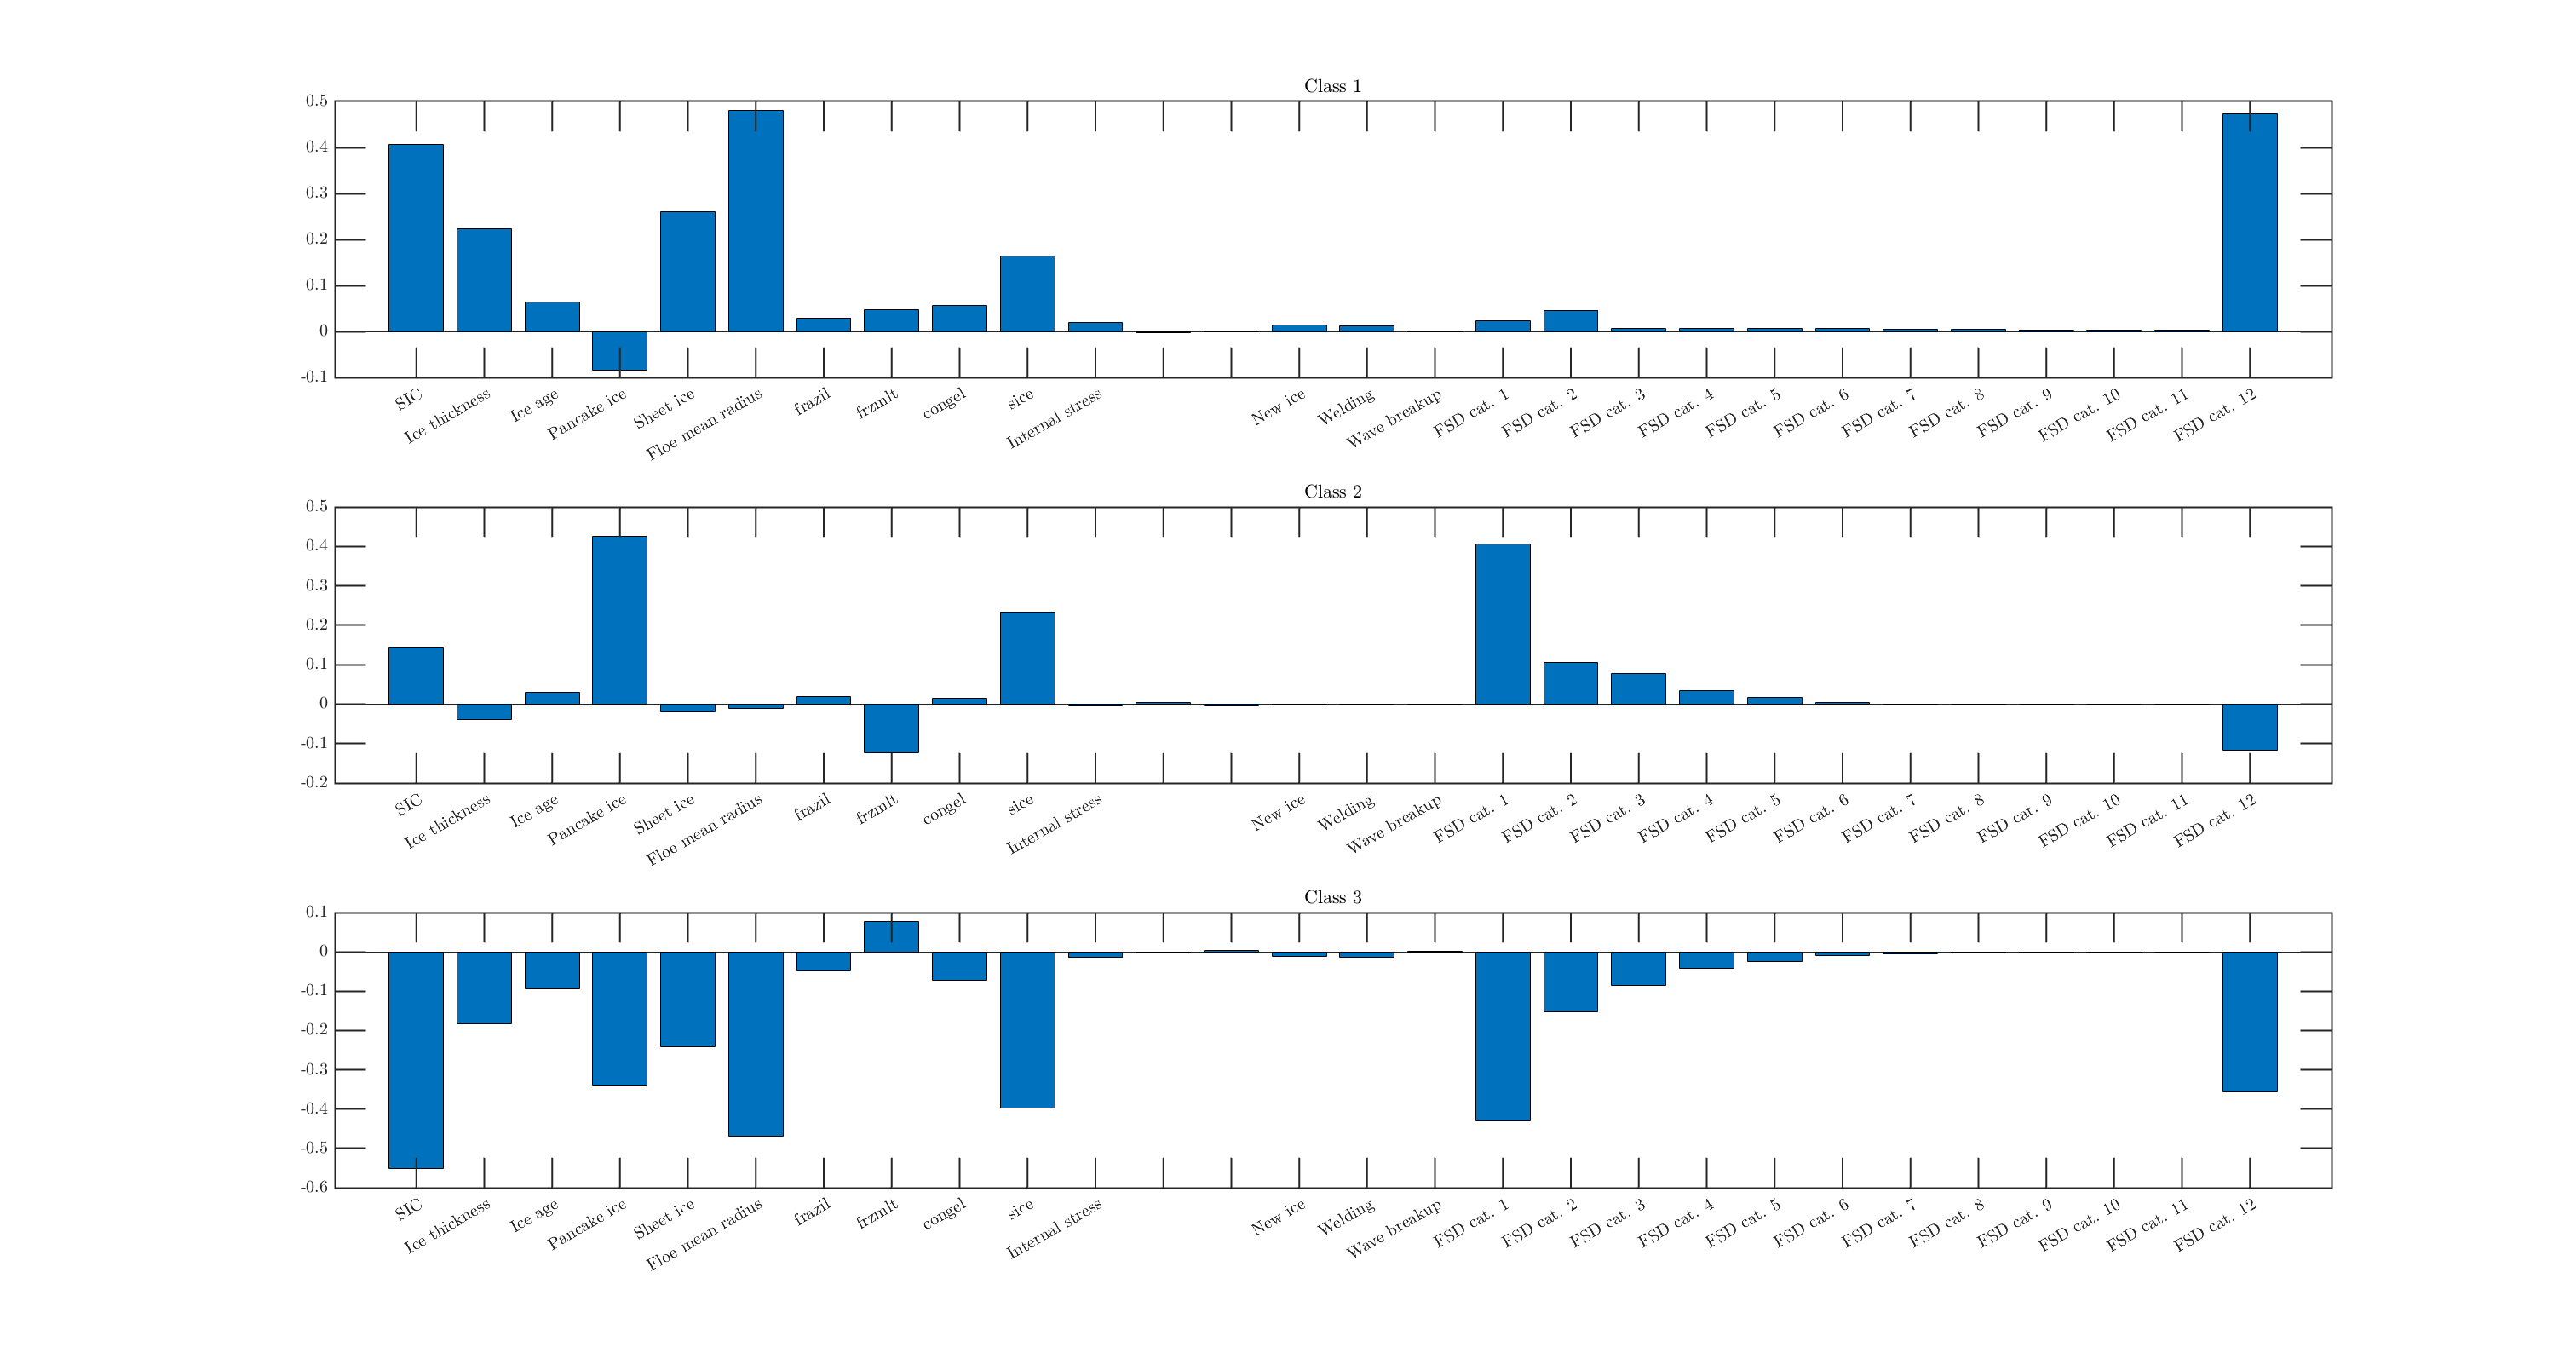



%exportgraphics(f,'map.pdf','ContentType','vector')

    % Calculate the width of the MIZ

    % CHECK WHAT number MIZ is !!!!!!!!
%     [MIZ_width, miz_class] = calculate_miz_width(pca_filenames(file_number,:),sector,k_means);
% 
%     conFigure(11,3)
%     f = figure;
%     stairs(lon(1:end-1,1),MIZ_width(1:end-1))
%     ylabel('MIZ width [km]')
%     xlabel('Longitude [$^\circ$]')
%     xlim([0,360])
% 
%     %exportgraphics(f,'mizwidth.pdf','ContentType','vector')

% sprintf('The mean MIZ width is: %g [km]',mean(MIZ_width(1:end-1)))
conFigure(13)
f = figure('Position',[100, 100, 100, 100]);
set(gcf,'Visible', 'on')
for i = 1:num_clusters
  subplot(num_clusters,1,i)
  bar(C(i,:) - mean(C))
  xticks(1:length(C(i,:)))
  set(gca, 'XTickLabel',label_vec)
  title(sprintf('Class %g',i))
end

%exportgraphics(f,'kmeans_C.pdf','ContentType','vector')

% for i = 1:num_clusters
%  subplot(num_clusters,1,i)
%  temp = C(i,:);
%  %idx = abs(temp) > 1/sqrt(length(temp));
%  loadings = temp(idx);
%  loadings_label = label_vec(idx);
%  bar(loadings)
%  xticks(1:length(loadings))
%  set(gca, 'XTickLabel',loadings_label)
%  title(sprintf('PCA component %g',i))
%  ylabel('Loadings')
% end




## What does the average cell in each class look like?

X_temp = [];
[~,~,dep] = size(X_new_unstandard);
for i = 1:dep
    X_temp = [X_temp; X_new_unstandard(:,:,i)];
end

X_temp = [X_temp(:,1:end-2), idx];

for i = 1:num_clusters
    index_class_data = X_temp(:,end) == i;
    class_data = X_temp(index_class_data,1:end-1);
    average_stats(i,:) = mean(class_data);
end

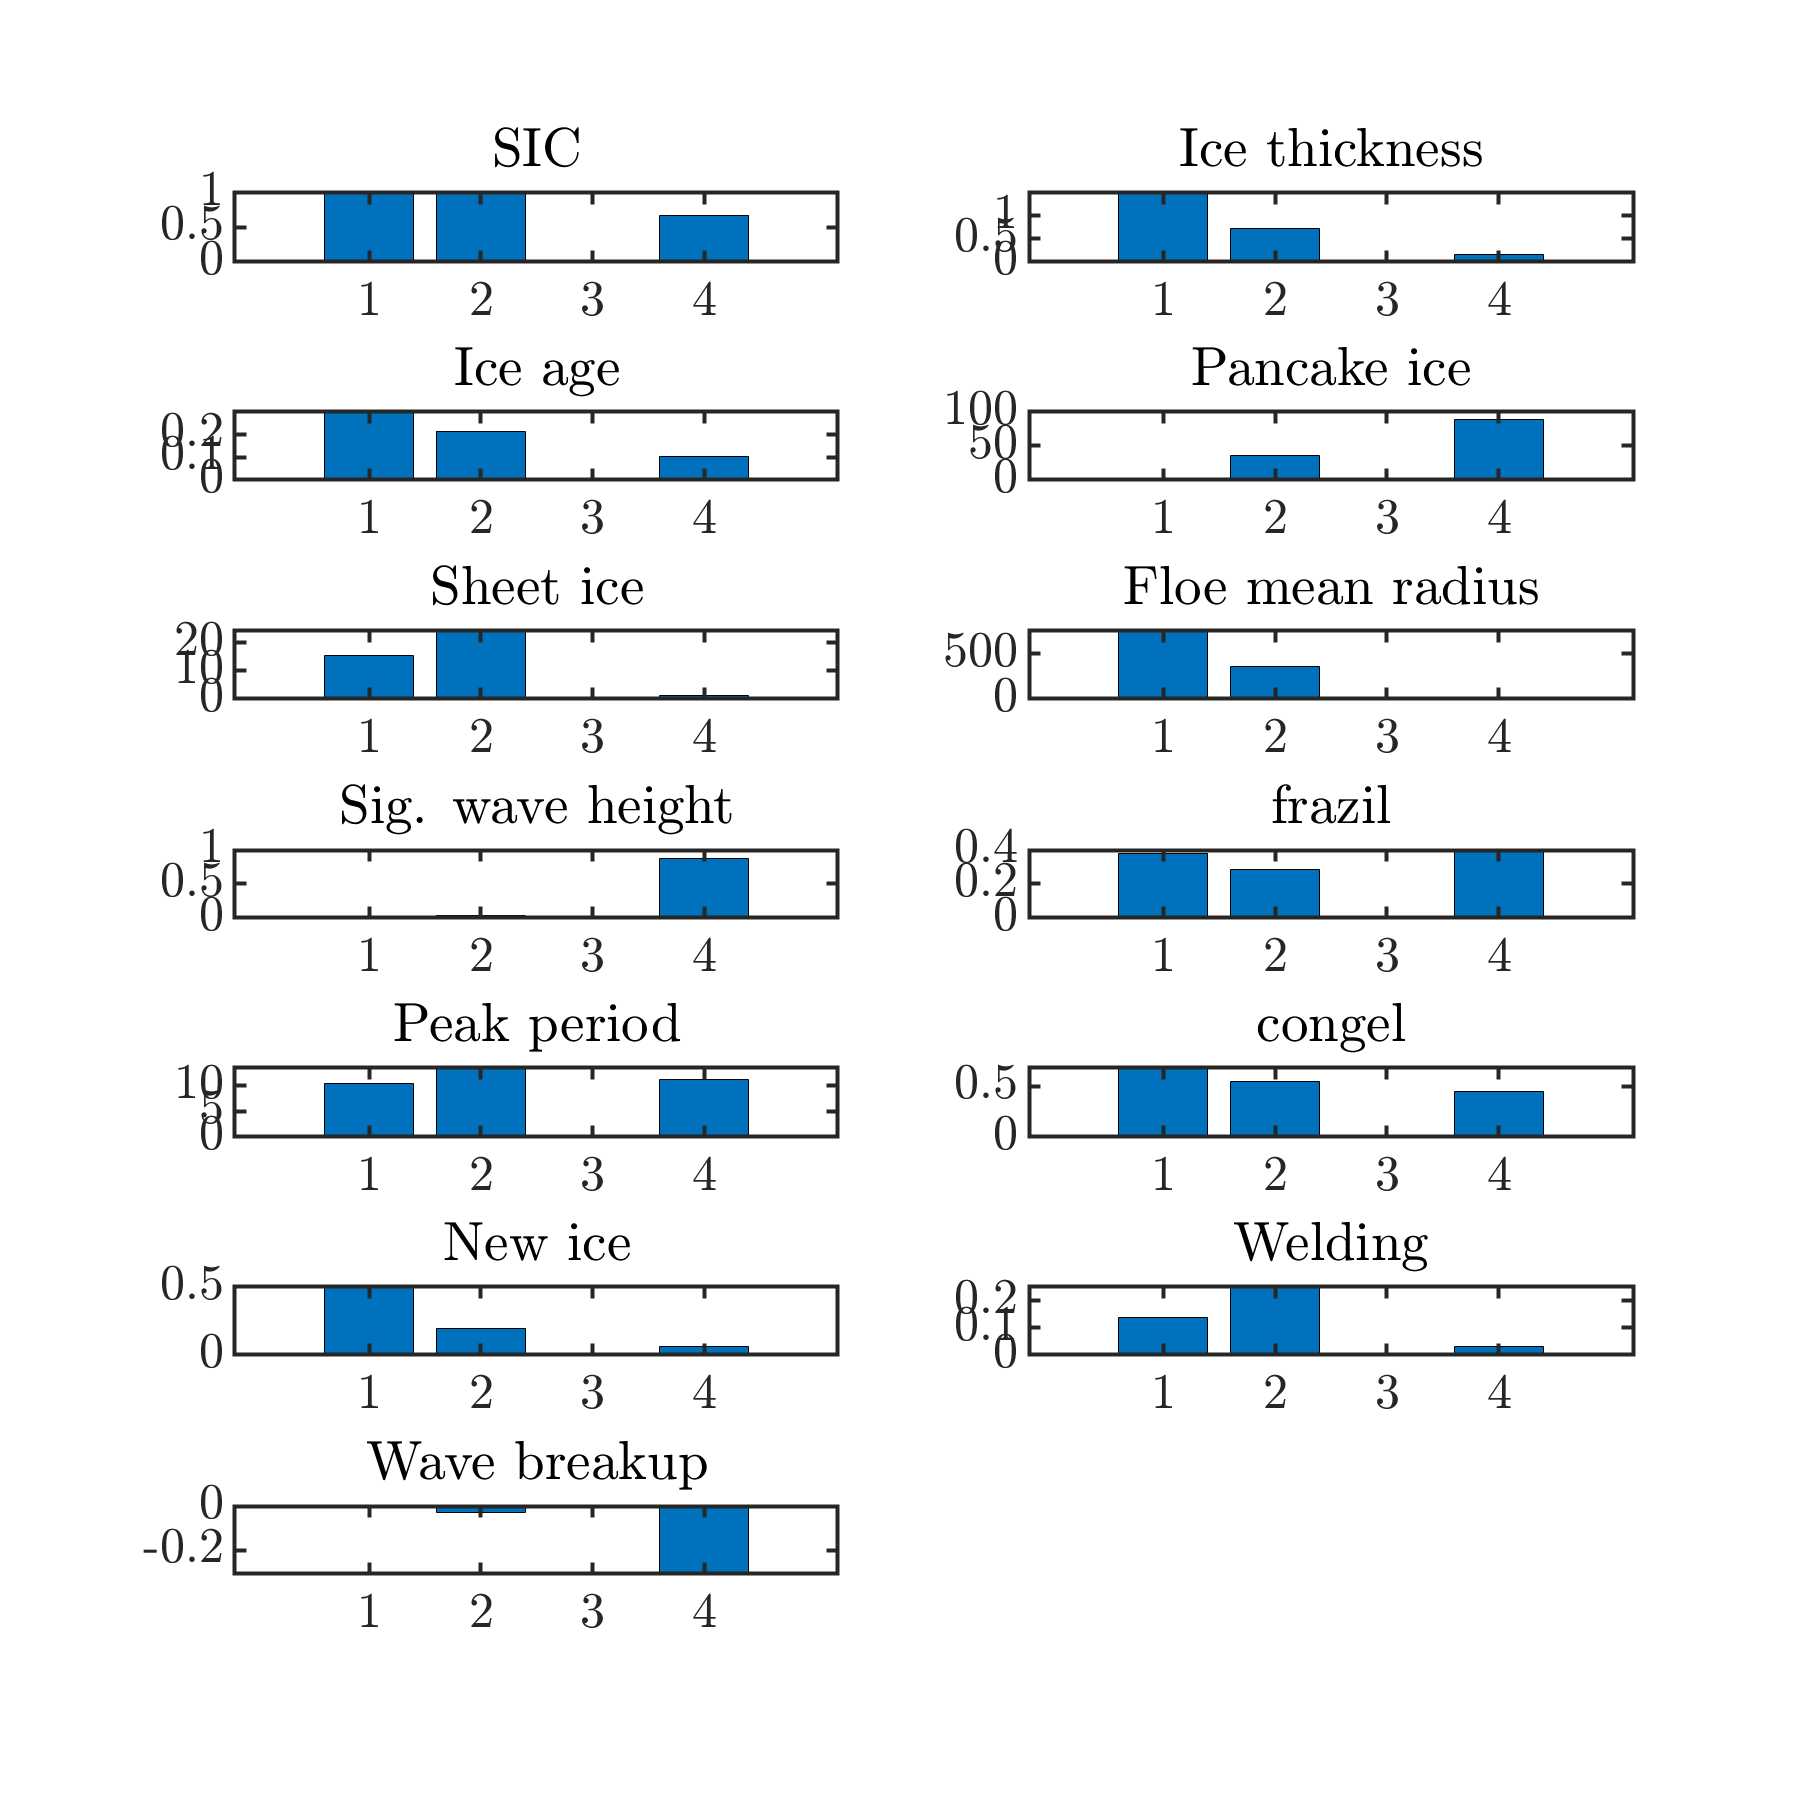

close all
conFigure(30)
f = figure('Position',[100, 100, 100, 100]);
%set(gcf,'Visible', 'on')
for i = 1:13
  subplot(7,2,i)
  bar(average_stats(:,i))
  xticks(1:length(average_stats(:,i)))
  %set(gca, 'XTickLabel',label_vec)
  title(label_vec{i})
end
exportgraphics(f,'statcomp.pdf','ContentType','vector')

## FSD plot

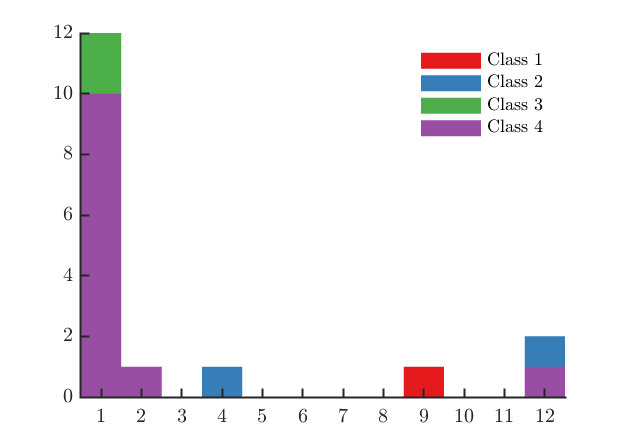

close all

map = brewermap(4,'Set1');
H1 = average_stats(1,14:end);
H2 = average_stats(2,14:end);
H3 = average_stats(3,14:end);
H4 = average_stats(4,14:end);

figure
set(gcf,'Visible', 'on')
histf(H1,1:12,'facecolor',map(1,:),'facealpha',.3,'edgecolor','none')
hold on
histf(H2,1:12,'facecolor',map(2,:),'facealpha',.5,'edgecolor','none')
histf(H3,1:12,'facecolor',map(3,:),'facealpha',.5,'edgecolor','none')
histf(H4,1:12,'facecolor',map(4,:),'facealpha',.5,'edgecolor','none')
box off
axis tight
%legalpha('H1','H2','H3','location','northwest')
%legend boxoff
legalpha("Class 1","Class 2","Class 3","Class 4",'location','northeast')
legend boxoff

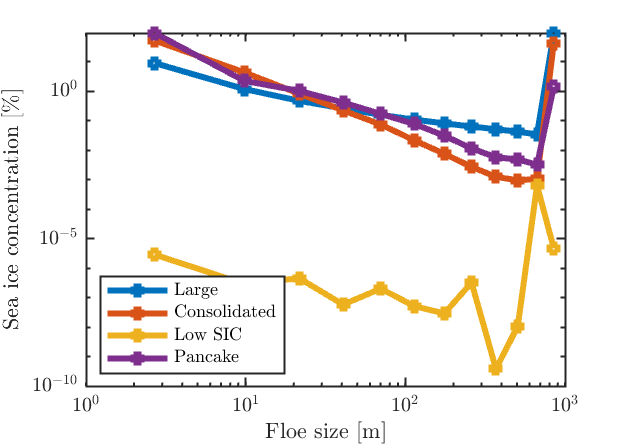



NFSD = ncread(filenames(1,:),"NFSD");
NCAT = ncread(filenames(1,:),"NCAT");
f = figure;
set(gcf,'Visible', 'on')
loglog(NFSD,average_stats(:,14:end),'LineWidth',3,'LineStyle','-','Marker','s','MarkerSize',5)
legend(region_label,'location','southwest')
ylabel('Sea ice concentration [$\%$]')
xlabel('Floe size [m]')
exportgraphics(f,'floesizecomp.pdf','ContentType','vector')

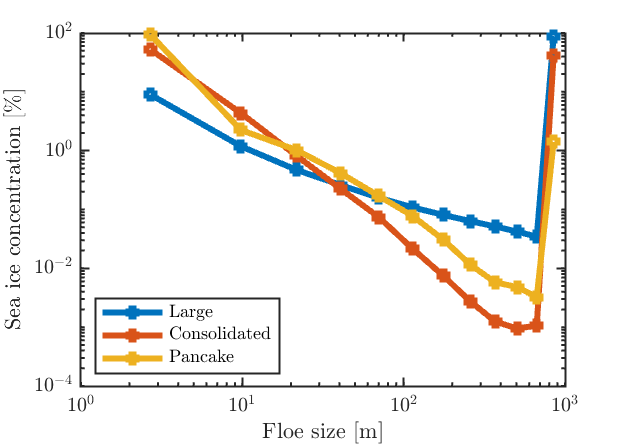


NFSD = ncread(filenames(1,:),"NFSD");
NCAT = ncread(filenames(1,:),"NCAT");
f = figure;
set(gcf,'Visible', 'on')
loglog(NFSD,average_stats([1,2,4],14:end),'LineWidth',3,'LineStyle','-','Marker','s','MarkerSize',5)
legend(region_label{[1,2,4]},'location','southwest')
ylabel('Sea ice concentration [$\%$]')
xlabel('Floe size [m]')
exportgraphics(f,'floesizecompminus3.pdf','ContentType','vector')

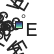




% Plot pancakes = 4/ aige = 3
file_number = 50;
var_num = 7; % SWH
pancake = (X_new(:,var_num) + mean_X(var_num,file_number)).*std_X(var_num,file_number);%X(:,4);
file_idx = pancake(row_file(file_number)+1:row_file(file_number+1));%idx;%
X_map = [file_idx, X_new(row_file(file_number)+1:row_file(file_number+1),end-1:end)];%[file_idx, X_new(:,end-1:end)];%
k_means = NaN.*ones(len,wid);
for i = 1:length(file_idx)
    lat_pos = near1(lat(180,:),X_map(i,2));
    lon_pos = near1(lon(:,180),X_map(i,3));
    k_means(lon_pos,lat_pos) = file_idx(i); 
end
%map_data = [X_new(:,end-1:end);
    aice = data_format_sector(pca_filenames(file_number,:),'aice',sector);
    ice_mask =  aice > 0.15;
    k_means(~ice_mask) = NaN;

f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-30]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off') 
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'grid', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,k_means)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    cmocean('deep')

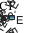

% PC1
% Make worldmap with colour matching
[lat,lon,~,ulat,ulon] = grid_read('om2');
[len,wid] = size(lat);
file_number = 2; % Days
row_file = [0,cumsum(row_idx)];
file_idx = score(row_file(file_number)+1:row_file(file_number+1),1);
file_idx = file_idx + abs(min(file_idx));
file_idx = file_idx./max(file_idx);
X_map = [file_idx, X_new(row_file(file_number)+1:row_file(file_number+1),end-1:end)];%[file_idx, X_new(:,end-1:end)];%
k_means = NaN.*ones(len,wid);
for i = 1:length(file_idx)
    lat_pos = near1(lat(180,:),X_map(i,2));
    lon_pos = near1(lon(:,180),X_map(i,3));
    k_means(lon_pos,lat_pos) = file_idx(i); 
end
%map_data = [X_new(:,end-1:end);
    aice = data_format_sector(pca_filenames(file_number,:),'aice',sector);
    ice_mask =  aice > 0.15;
    k_means(~ice_mask) = NaN;

f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-30]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off') 
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'grid', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,k_means)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    cmocean('deep')
    title('PC1')

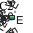



file_idx = score(row_file(file_number)+1:row_file(file_number+1),2);
file_idx = file_idx + abs(min(file_idx));
file_idx = file_idx./max(file_idx);
X_map = [file_idx, X_new(row_file(file_number)+1:row_file(file_number+1),end-1:end)];%[file_idx, X_new(:,end-1:end)];%
k_means = NaN.*ones(len,wid);
for i = 1:length(file_idx)
    lat_pos = near1(lat(180,:),X_map(i,2));
    lon_pos = near1(lon(:,180),X_map(i,3));
    k_means(lon_pos,lat_pos) = file_idx(i); 
end
%map_data = [X_new(:,end-1:end);
    aice = data_format_sector(pca_filenames(file_number,:),'aice',sector);
    ice_mask =  aice > 0.15;
    k_means(~ice_mask) = NaN;

f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-30]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off') 
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'grid', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,k_means)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    cmocean('haline')
    title('PC2')

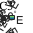



file_idx = score(row_file(file_number)+1:row_file(file_number+1),3);
file_idx = file_idx + abs(min(file_idx));
file_idx = file_idx./max(file_idx);
X_map = [file_idx, X_new(row_file(file_number)+1:row_file(file_number+1),end-1:end)];%[file_idx, X_new(:,end-1:end)];%
k_means = NaN.*ones(len,wid);
for i = 1:length(file_idx)
    lat_pos = near1(lat(180,:),X_map(i,2));
    lon_pos = near1(lon(:,180),X_map(i,3));
    k_means(lon_pos,lat_pos) = file_idx(i); 
end
%map_data = [X_new(:,end-1:end);
    aice = data_format_sector(pca_filenames(file_number,:),'aice',sector);
    ice_mask =  aice > 0.15;
    k_means(~ice_mask) = NaN;

f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-30]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off') 
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'grid', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,k_means)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    cmocean('haline')
    title('PC3')

    %%

## PC1 to timeframes

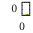

[lat,lon,~,~,~] = grid_read('om2');
clear pc_cube
% Make worldmap with colour matching
[len,wid] = size(lat);
[num_files,~] = size(pca_filenames);
coords = sector_coords(sector);
plot_type = "pc1";
row_file = [0,cumsum(row_idx)];
for file_number = 1:num_files
    if plot_type == "pc1"
        file_idx = score(row_file(file_number)+1:row_file(file_number+1),1);
        file_idx = file_idx + abs(min(file_idx));
        file_idx = file_idx./max(file_idx);
    else
        file_idx = idx(row_file(file_number)+1:row_file(file_number+1));
    end
    X_map = [file_idx, X_new(row_file(file_number)+1:row_file(file_number+1),end-1:end)];
    pc_cube(:,:,file_number) = NaN.*ones(len,wid);
    for i = 1:length(file_idx)
        lat_pos = near1(lat(180,:),X_map(i,2));
        lon_pos = near1(lon(:,180),X_map(i,3));
        pc_cube(lon_pos,lat_pos,file_number) = file_idx(i); 
    end
    aice = data_format_sector(pca_filenames(file_number,:),'aice',sector);
    ice_mask =  aice > 0.15;
    %for i = 1:len
    %    for j = 1:wid
    %        pc_cube(~ice_mask(i),~ice_mask(j),file_number) = NaN;
    %    end
    %end
    
end
save('pc_cube_june_sep_2019.mat','pc_cube');
imagescn(lon',lat',pc_cube(:,:,1)')

#### GIF OF KMEANS OR PCA

[lat,lon,~,ulat,ulon] = grid_read('om2');
clear X_map MIZ_width
% Make worldmap with colour matching
uarea = data_format(filenames(1,:),"uarea");
[len,wid] = size(lat);
[num_files,~] = size(pca_filenames);
sector = "EA";
coords = sector_coords(sector);
font_size = 5;
plot_type = "kmeans";
plotting = "off";
conFigure(11)
for file_number = 1:num_files-1
    row_file = [0,cumsum(row_idx)];
    if plot_type == "pc1"
        file_idx = score(row_file(file_number)+1:row_file(file_number+1),1);
        file_idx = file_idx + abs(min(file_idx));
        file_idx = file_idx./max(file_idx);
    elseif plot_type == "kmeans"
        index_lat = X_new(:,end-1) == X_new(1,end-1);
        index_lon = X_new(:,end) == X_new(1,end);
        index_both = index_lat.*index_lon;
        row_file = find(index_both);%[0,cumsum(row_idx)];
        row_vec = row_file(file_number)+1:row_file(file_number+1);
        file_idx = idx(row_vec);
    end
    [aice, sector_mask] = data_format_sector(pca_filenames(file_number,:),'aice',sector);
    X_map = [file_idx, X_new(row_vec,end-1:end)];%[file_idx, X_new(:,end-1:end)];%
    k_means = NaN.*ones(len,wid);
    for i = 1:length(file_idx)
        [lon_pos,lat_pos,~] = near2(lon,lat,X_map(i,3),X_map(i,2));
        k_means(lon_pos,lat_pos) = file_idx(i); 
        k_means(~sector_mask) = NaN;
    end
    
        %ice_mask =  aice > 0.15;
        %k_means(~ice_mask) = NaN;
    if plotting == "on"
        f = figure;
        set(gcf,'Visible', 'off')
        w = worldmap('world');
            %axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            %setm(w, 'Origin', [-90 0 0]);
            %setm(w, 'maplatlimit', [-90,-50]);
           % setm(w, 'maplonlimit', [coords(1,2),coords(3,2)]);
            axesm eqdcylin; 
            setm(w, 'Origin', [0 28 0]); 
            setm(w, 'maplatlimit', [-75,-50]); setm(w, 'maplonlimit', [1,150]); 
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off') 
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'grid', 'off');
            setm(w, 'labelrotation', 'on')
            pcolorm(lat,lon,k_means)
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.5 0.5])
            colorbar; cmocean('deep');
            title(pca_dates(file_number,:),'Color','black','FontSize',font_size+5)
            
            if plot_type == "pc1"
                caxis([0,1])
            elseif plot_type == "kmeans"
                cb = colorbar; cmocean('deep',num_clusters)
                cb.TickLabels = region_label; cb.Ticks = 1:num_clusters;
                cb.Location = 'southoutside';%cb.Location = 'northoutside';
                caxis([1,num_clusters])
            end
    end
    % Calculate the width of the MIZ
    % CHECK WHAT number MIZ is !!!!!!!!
    [MIZ_width(file_number,:), miz_class, MIZ_zone] = calculate_miz_width(pca_filenames(file_number,:),sector,k_means,1);
    

    % Calculate the perimeter and area of the zones
    for rgn_number = 1:num_clusters
        region_data = k_means == rgn_number;
        [len, wid] = size(k_means);
        perimeter_region(rgn_number,file_number) = find_perimeter(region_data,len,wid);

        % Area
        area_region(rgn_number, file_number) = sum(sum(uarea.*region_data));
    end
    if plotting == "on"
        if file_number == 1
            gif('kmeans_EA_SA_noMinSIC_stndzd_4class.gif','DelayTime',0.5,'resolution',500,'overwrite',true)
        else
            gif
        end
    end
    clear aice ice_mask k_means file_idx X_map
end

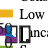

date_label = datetime(dirdates);
conFigure(11)
figure
subplot(2,3,1)
plot(date_label(1:end-1),[perimeter_region; sum(perimeter_region)],'LineWidth',5)
ylabel('Perimeter [block edges]')
%legend(region_label,'Location','southeast')

subplot(2,3,2)
plot(date_label(1:end-1),[area_region.*1e-6.*1e-6; sum(area_region.*1e-6.*1e-6)],'LineWidth',5)
ylabel('Area [million km$^2$]')
%legend(region_label,'Location','southeast')

% Create a tile on the right column to get its position
legend_label = region_label;
legend_label{end+1} = 'Sum of regions';
ax = subplot(2,3,3,'Visible','off');
axPos = ax.Position;
delete(ax)
% Construct a Legend with the data from the sub-plots
hL = legend(legend_label);
% Move the legend to the position of the extra axes
hL.Position(1:2) = axPos(1:2);

subplot(2,3,4)
perim_per_area = perimeter_region./(area_region.*1e-6.*1e-6);
plot(date_label(1:end-1),perim_per_area,'LineWidth',5)
ylabel('Perimeter per Area [block per million km$^2$]')
%text(1,1,sprintf("$sigma =$ %g",std(perimeter_region'./(area_region./1000)')))
% ta = annotation('textarrow', [0.76 0.83], [0.71 0.71]);
% ta.String = sprintf("$\sigma =$ %g",std(perimeter_region(4,:)'./(area_region(4,:)./1000)'));
% ta.Interpreter = "latex";
%legend(region_label,'Location','southeast')



diff_perim = perim_per_area(:,2:end)' - perim_per_area(:,1:end-1)';
subplot(2,3,5)
bar(std(diff_perim))
xticklabels(region_label)
ylabel('S.D. $\Delta$ perimeter per area')

% The sum of the areas is ignoring sea ice concentration in each cell
% (that's why its overestimating the total SIC)







%load("miz_width_may_sep_2019_4_classes.mat")

Error using load
Unable to find file or directory 'miz_width_may_sep_2019_4_classes.mat'.

lon_len = length(MIZ_width);
lon_vector = 1:60:lon_len-20;
lon_matrix = repmat(lon(lon_vector,:),length(lon_vector),1);
date_label = datetime(dirdates);
for i = 1:length(lon_vector)-1
    legend_label{i} = strcat(sprintf('Lon %g',lon_vector(i)),'$^\circ$ E');
end
g(1,1)=gramm('x',reshape(lon_matrix,1,numel(lon_matrix))','y',reshape(MIZ_width(:,lon_vector),1,numel(MIZ_width(:,lon_vector)))');
g(1,3)=copy(g(1));
conFigure(11)
f = figure('Position',[100 100 800 550]);
subplot(4,1,1)
sgtitle('MIZ width')
area(date_label,MIZ_width(:,lon_vector))
ylabel('Pancake MIZ width [km]')
legend(legend_label,'Interpreter','latex','Location','eastoutside')

%xticklabels(date_label)
subplot(4,1,2)
yyaxis left
plot(1:lon_len,median(MIZ_width,1))
ylabel 'Median [km]'
xlabel('Longitude $^\circ$ E')
yyaxis right
plot(1:lon_len,std(MIZ_width,1))
xlabel('Longitude $^\circ$ E')
ylabel 'STD, $\sigma$ [km]'
xline(280,'--','LineWidth',2)
xline(310,'--','LineWidth',2)
text(287,450,"Chile",'Rotation',0)
xlim([0,360])

subplot(4,1,3)
fanChart(1:lon_len,MIZ_width(:,:)');
ylim([0,1000])
ylabel('Pancake MIZ width [km]')
xlabel('Longitude $^\circ$ E')
xlim([0,360])

subplot(4,1,4)
fanChart(date_label,MIZ_width(:,:));
ylim([0,1000])
ylabel('Pancake MIZ width [km]')

%exportgraphics(f,'miz_stat.png','ContentType','image')

%subplot(4,1,4)
%boxplot(lon_vector,MIZ_width(:,lon_vector)')
%g(1,4).stat_summary('geom',{'bar','black_errorbar'});
%g.draw();

%ylim([0,1000])
%ksdensity(date_label,MIZ_width(:,:))
%yyaxis left
%plot(1:lon_len,median(MIZ_width,1))
%ylabel 'Median [km]'
%xlabel('Longitude $^\circ$ E')
%yyaxis right
%plot(1:lon_len,std(MIZ_width,1))
%xlabel('Longitude $^\circ$ E')
%ylabel 'STD, $\sigma$ [km]'
%xline(280,'--','LineWidth',2)
%xline(310,'--','LineWidth',2)
%text(287,450,"Chile",'Rotation',0)

%text(3/2*pi,0,str)

clc
region_label

region_label = 1×4 cell array
    {'Large'}    {'Consolidated'}    {'Low SIC'}    {'Pancake'}


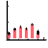

clf
clear g
g(1)=gramm('x',reshape(lon_matrix,1,numel(lon_matrix))','y',reshape(MIZ_width(:,lon_vector),1,numel(MIZ_width(:,lon_vector)))');
g(1)=copy(g(1));
g(1).stat_summary('geom',{'bar','black_errorbar'});
g.set_names('x','Longitude','y','MIZ width [km]','color','# Cyl');
gf = copy(g);
conFigure(11)
figure;
g.draw();
xlabel('Longitude')

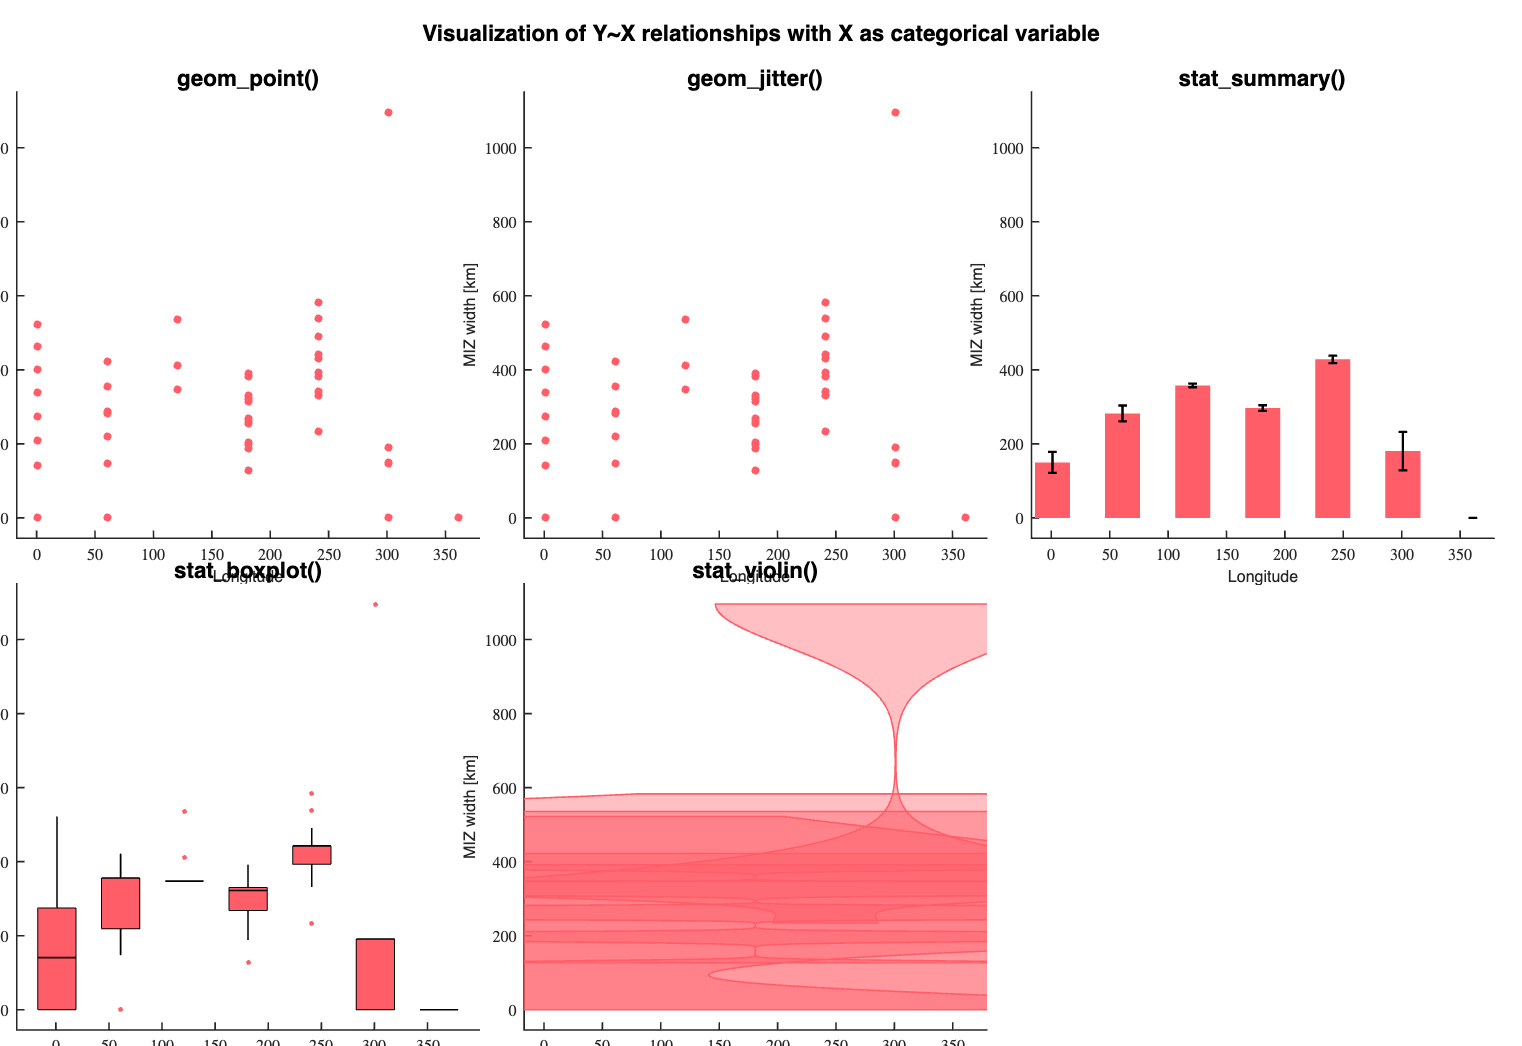

lon_matrix = repmat(lon_vector,122,1);
g(1,1)=gramm('x',reshape(lon_matrix,1,numel(lon_matrix))','y',reshape(MIZ_width(:,lon_vector),1,numel(MIZ_width(:,lon_vector)))');
g(1,2)=copy(g(1));
g(1,3)=copy(g(1));
g(2,1)=copy(g(1));
g(2,2)=copy(g(1));

%Raw data as scatter plot
g(1,1).geom_point();
g(1,1).set_title('geom_point()');

%Jittered scatter plot
g(1,2).geom_jitter('width',0.4,'height',0);
g(1,2).set_title('geom_jitter()');

%Averages with confidence interval
g(1,3).stat_summary('geom',{'bar','black_errorbar'});
g(1,3).set_title('stat_summary()');

%Boxplots
g(2,1).stat_boxplot();
g(2,1).set_title('stat_boxplot()');

%Violin plots
g(2,2).stat_violin('fill','transparent');
g(2,2).set_title('stat_violin()');

%These functions can be called on arrays of gramm objects
g.set_names('x','Longitude','y','MIZ width [km]','color','# Cyl');
g.set_title('Visualization of Y~X relationships with X as categorical variable');

gf = copy(g);

figure('Position',[100 100 800 550]);
g.draw();

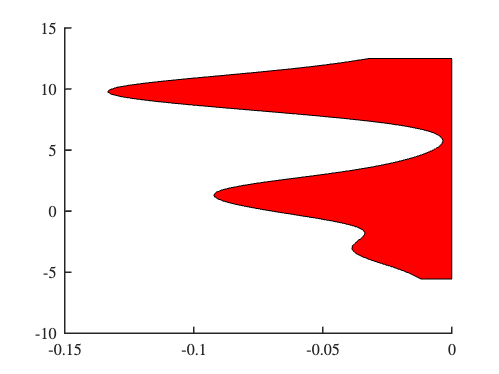

close all   
rng(5)
mu = [0,10];
sigma = [5,0;0,1];
gm = gmdistribution( mu,sigma );
data = random(gm,30);
data = data(:);
xvalues = linspace( prctile(data,1), prctile(data,99), 100 );
[f,xi] = ksdensity( data(:),xvalues,'Bandwidth',1,'BoundaryCorrection','reflection');
 
figure; patch( 0-[f,zeros(1,numel(xi),1),0],[xi,fliplr(xi),xi(1)],'r' )

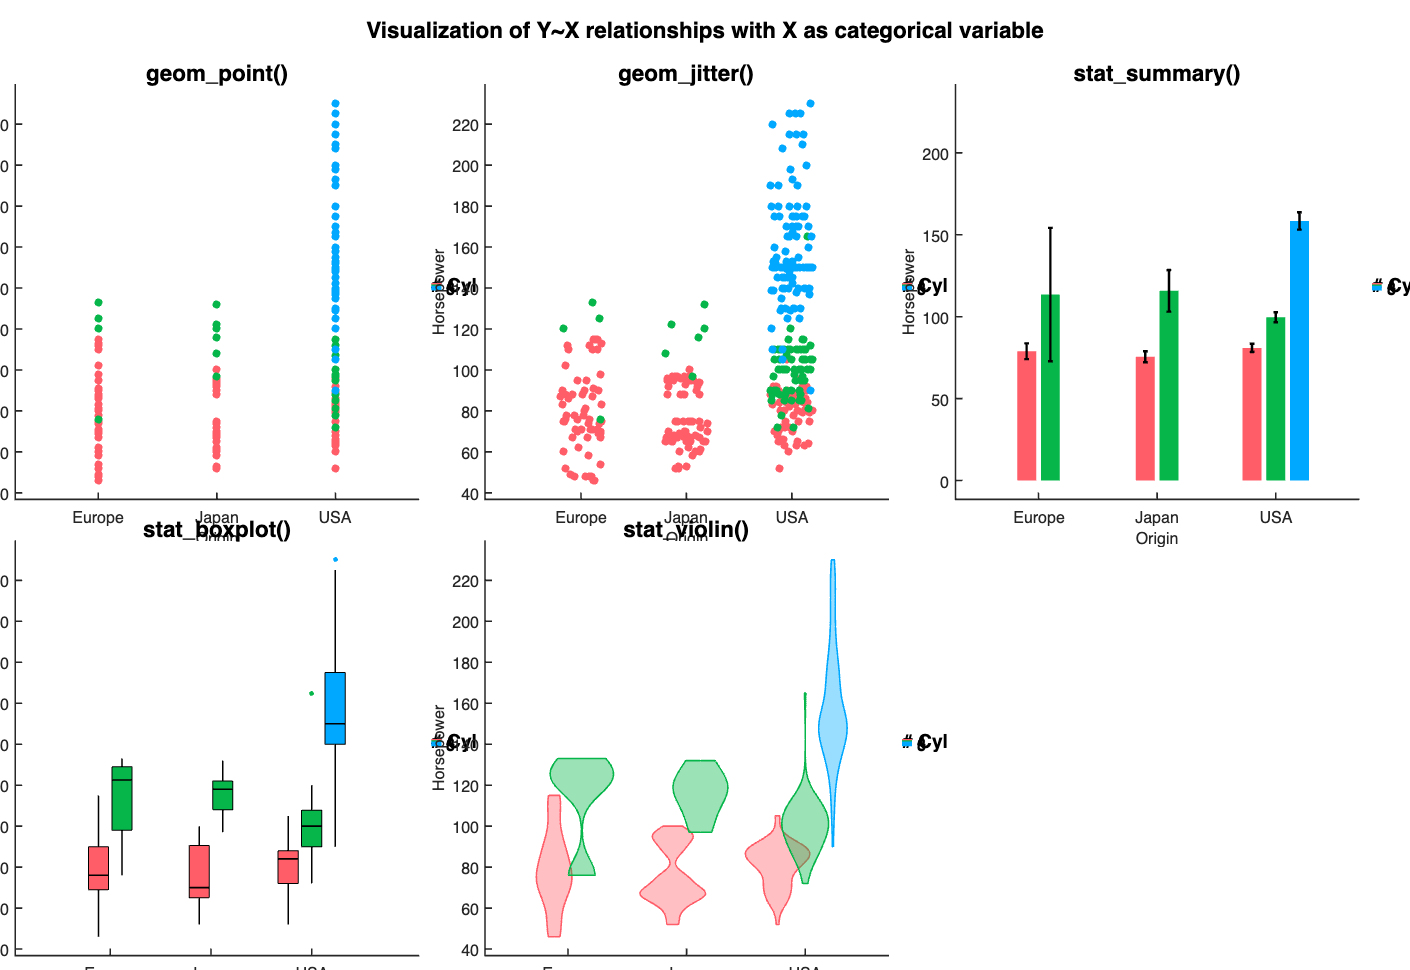

load example_data;
clear g

g(1,1)=gramm('x',cars.Origin_Region,'y',cars.Horsepower,'color',cars.Cylinders,'subset',cars.Cylinders~=3 & cars.Cylinders~=5);
g(1,2)=copy(g(1));
g(1,3)=copy(g(1));
g(2,1)=copy(g(1));
g(2,2)=copy(g(1));

%Raw data as scatter plot
g(1,1).geom_point();
g(1,1).set_title('geom_point()');

%Jittered scatter plot
g(1,2).geom_jitter('width',0.4,'height',0);
g(1,2).set_title('geom_jitter()');

%Averages with confidence interval
g(1,3).stat_summary('geom',{'bar','black_errorbar'});
g(1,3).set_title('stat_summary()');

%Boxplots
g(2,1).stat_boxplot();
g(2,1).set_title('stat_boxplot()');

%Violin plots
g(2,2).stat_violin('fill','transparent');
g(2,2).set_title('stat_violin()');

%These functions can be called on arrays of gramm objects
g.set_names('x','Origin','y','Horsepower','color','# Cyl');
g.set_title('Visualization of Y~X relationships with X as categorical variable');

gf = copy(g);

figure('Position',[100 100 800 550]);
g.draw();

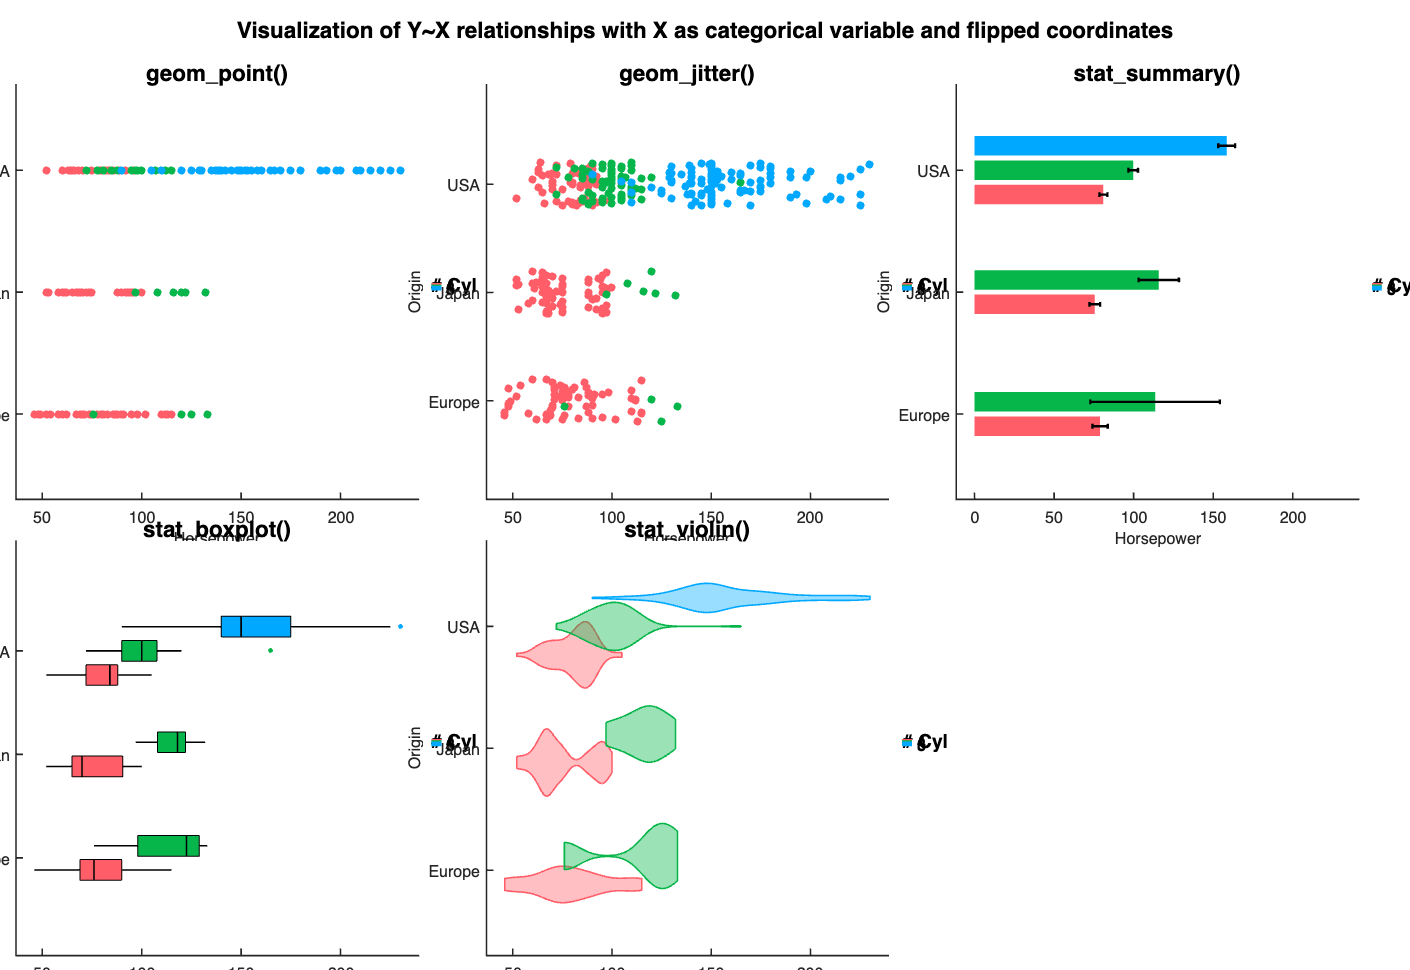


gf.set_title('Visualization of Y~X relationships with X as categorical variable and flipped coordinates');
figure('Position',[100 100 800 550]);
gf.coord_flip();
gf.draw();

## Auto correlation of PMIZ

for file_number = 1:num_files
    row_file = [0,cumsum(row_idx)];

    file_idx = idx(row_file(file_number)+1:row_file(file_number+1));
    X_map = [file_idx, X_new(row_file(file_number)+1:row_file(file_number+1),end-1:end)];
    k_means = NaN.*ones(len,wid);
    for i = 1:length(file_idx)
        lat_pos = near1(lat(180,:),X_map(i,2));
        lon_pos = near1(lon(:,180),X_map(i,3));
        k_means(lon_pos,lat_pos) = file_idx(i); 
    end
        aice = data_format_sector(pca_filenames(file_number,:),'aice',sector);
        ice_mask =  aice > 0.15;
        k_means(~ice_mask) = NaN;
        miz = k_means == 3;
        MIZ_vec(:,file_number) = reshape(miz,[numel(miz),1]);

end
% indexnan = isnan(MIZ_vec);
% MIZ_vec(indexnan) = 0;
% 
[len, wid] = size(MIZ_vec);
miz_only_vec = [];
for i = 1:len
    temp = MIZ_vec(i,:) == 1;
    if sum(temp) > 0
        miz_only_vec = [miz_only_vec; temp];
    end

end
%miz_index = find(MIZ_vec(:,1) == 1);
indexnan = isnan(miz_only_vec);
miz_only_vec(indexnan) = 0;

[acf,lags] = autocorr(miz_only_vec(1,:));

acf =     1.0000   -0.0168   -0.0169   -0.0171   -0.0172   -0.0173   -0.0092   -0.0093   -0.0094   -0.0096   -0.0097   -0.0098   -0.0100   -0.0101   -0.0102   -0.0104   -0.0105   -0.0107   -0.0108   -0.0109   -0.0111


lags =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


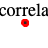

% SUM = size of the MIZ approx
figure
autocorr(sum(miz_only_vec(:,:),1),NumLags=wid-1);


for file_number = 1:num_files-1
    row_file = [0,cumsum(row_idx)];
    % File #1
    if plot_type == "pc1"
        file_idx = score(row_file(file_number)+1:row_file(file_number+1),1);
        file_idx = file_idx + abs(min(file_idx));
        file_idx = file_idx./max(file_idx);
    elseif plot_type == "kmeans"
        file_idx = idx(row_file(file_number)+1:row_file(file_number+1));
    end
    X_map = [file_idx, X_new(row_file(file_number)+1:row_file(file_number+1),end-1:end)];
    k_means = NaN.*ones(len,wid);
    for i = 1:length(file_idx)
        lat_pos = near1(lat(180,:),X_map(i,2));
        lon_pos = near1(lon(:,180),X_map(i,3));
        k_means(lon_pos,lat_pos) = file_idx(i); 
    end
    aice = data_format_sector(pca_filenames(file_number,:),'aice',sector);
    ice_mask =  aice > 0.15;
    k_means(~ice_mask) = NaN;
    % File #2
    if plot_type == "pc1"
        file_idx = score(row_file(file_number)+1:row_file(file_number+1),1);
        file_idx = file_idx + abs(min(file_idx));
        file_idx = file_idx./max(file_idx);
    elseif plot_type == "kmeans"
        file_idx = idx(row_file(file_number+1)+1:row_file(file_number+1+1));
    end
    X_map = [file_idx, X_new(row_file(file_number+1)+1:row_file(file_number+1+1),end-1:end)];
    k_means2 = NaN.*ones(len,wid);
    for i = 1:length(file_idx)
        lat_pos = near1(lat(180,:),X_map(i,2));
        lon_pos = near1(lon(:,180),X_map(i,3));
        k_means2(lon_pos,lat_pos) = file_idx(i); 
    end
    aice = data_format_sector(pca_filenames(file_number+1,:),'aice',sector);
    ice_mask =  aice > 0.15;
    k_means2(~ice_mask) = NaN;

    correlation_matrix = k_means.*k_means2;
    index_nan = isnan(correlation_matrix);
    numerator = sum(sum(~index_nan));
    index_nan = isnan(k_means);
    denominator =  sum(sum(~index_nan));
    fraction(file_number) = numerator/denominator;

end

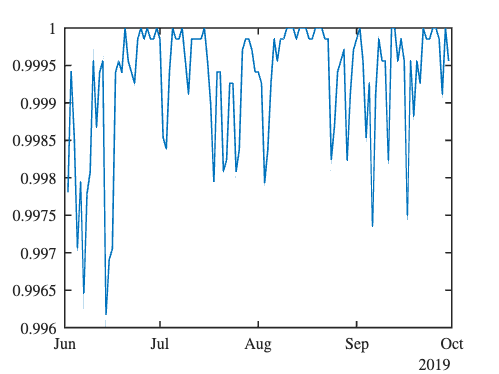

f = figure;
plot(date_label(2:end),fraction)


% conFigure(11,3)
% f = figure;
% stairs(lon(1:end-1,1),MIZ_width(2,1:end-1))
% ylabel('MIZ width [km]')
% xlabel('Longitude [$^\circ$]')
% xlim([0,360])
% 
% %exportgraphics(f,'mizwidth.pdf','ContentType','vector')
% 
% sprintf('The mean MIZ width is: %g [km]',mean(MIZ_width(1:end-1)))

miz_def = 3; % specify what class is MIZ
for file_number = 1:num_files
    row_file = [0,cumsum(row_idx)];

    if plot_type == "pc1"
        file_idx = score(row_file(file_number)+1:row_file(file_number+1),1);
        file_idx = file_idx + abs(min(file_idx));
        file_idx = file_idx./max(file_idx);
    elseif plot_type == "kmeans"
        file_idx = idx(row_file(file_number)+1:row_file(file_number+1));
    end
    X_map = [file_idx, X_new(row_file(file_number)+1:row_file(file_number+1),end-1:end)];
    k_means = NaN.*ones(len,wid);
    for i = 1:length(file_idx)
        lat_pos = near1(lat(180,:),X_map(i,2));
        lon_pos = near1(lon(:,180),X_map(i,3));
        k_means(lon_pos,lat_pos) = file_idx(i); 
    end
        aice = data_format_sector(pca_filenames(file_number,:),'aice',sector);
        ice_mask =  aice > 0.15;
        k_means(~ice_mask) = NaN;
    %conFigure(11,3)
    [MIZ_width(file_number,:), miz_class, MIZ_zone] = calculate_miz_width(pca_filenames(file_number,:),sector,k_means,miz_def);
%     f = figure;
%     stairs(lon(1:end-1,1),MIZ_width(file_number,1:end-1))
%     ylabel('MIZ width [km]')
%     xlabel('Longitude [$^\circ$]')
%     xlim([0,280])
%     ylim([0,2000])
%     if file_number == 1
%         gif('mizwidth_test.gif','DelayTime',0.5,'resolution',500,'overwrite',true)
%     else
%         gif
%     end
end



## Gif of MIZ

close all
conFigure(30)
%% Clustering gifs
% Columns are data
sector = "SH";
historydir = '/Users/noahday/Maths1/access-forcing-2010-fixed-ic/history/2019/';
line_width = 2;
FigWidth = 1920;
FigHeight = 1920;
BufferWidth = 200;
Height = 100;
a = dir([historydir '/*.nc']);
n_files = numel(a);
font_size = 20;
clear filenames dirdates MIZ_width_year
for i = 1:n_files
   filenames(i,:) = strcat(historydir,a(i).name);
   dirdates(i,:) = a(i).name(6:end-3);
end

f= figure('PaperPositionMode','manual','visible','off');
f.Position = [1 1 FigWidth FigHeight];
    AX = gca;
    f.Resize = 'off'; f.Units = 'points'; f.PaperUnits = 'points';
    AX.Units = 'points'; AX.Clipping = 'on'; AX.PositionConstraint = 'innerposition';
    AX.InnerPosition = [0 0 FigWidth-BufferWidth FigHeight-Height]*72/96; % converting from pixels to points
    f.OuterPosition = [0 0 FigWidth FigHeight]*72/96; % converting from pixels to points
    f.PaperPosition = [0 0 FigWidth FigHeight]*72/96;% converting from pixels to points
    camlight
    set(gca,'color','w')
    set(gcf,'color','w')

for loop_idx = 1:n_files
    [X_total]= read_data_vec(filenames(loop_idx,:),sector,var_list);
    % Step 0: removing NaNs
    idx1 = isnan(X_total);
    idx = logical(idx1);%;|logical(idx2);
    [len, wid] = size(X_total);
    clear X_new
    count = 1;
    for j = 1:len
        if sum(idx(j,:)) == 0
            X_new(count,:) = X_total(j,:);
        count  = count + 1;
        end
    end
    X_new_unstandard = X_new;
    % Step 1: Standardization
    wid = wid-2;
    for j = 1:wid
        % Calculate mean
        mean_X(j) = mean(X_new(:,j));
        % Calculate standard deviation
        std_X(j) = std(X_new(:,j));
        % Standardise the data
        X_new(:,j) = (X_new(:,j) - mean_X(j))/std_X(j);
    end
    
    % Step 2: Covariance analysis
    X_cov = X_new(:,1:wid);
    C = cov(X_cov);
    
    %% plotting cluster analysis
    %PCA
    figure;
    [coeff,score,latent,tsquared,explained] = pca(X_cov);
    % The rows of coeff contain the coefficients for the five ice variables, and its columns correspond to five principal components.
    % Each column of score corresponds to one principal component. 
    % The vector, latent, stores the variances of the five principal components.
    
    % Reconstruct the centered ingredients data.
    Xcentered = score*coeff';
    X = score(:,1:2);
    num_clusters = 2;
    [idx,C] = kmeans(X,num_clusters);
    
    x1 = linspace(min(X(:,1)),max(X(:,1)),1000);%min(X(:,1)):0.5:max(X(:,1));
    x2 = linspace(min(X(:,2)),max(X(:,2)),1000);%min(X(:,2)):0.5:max(X(:,2));
    [x1G,x2G] = meshgrid(x1,x2);
    XGrid = [x1G(:),x2G(:)]; % Defines a fine grid on the plot
    
    idx2Region = kmeans(XGrid,num_clusters,'MaxIter',200,'Start',C);
 

    % Make worldmap with colour matching
    [len,wid] = size(lat);
    X_map = [idx, X_new(:,end-1:end)];
    k_means = NaN.*ones(len,wid);
    for i = 1:length(idx)
        lat_pos = near1(lat(180,:),X_map(i,2));
        lon_pos = near1(lon(:,180),X_map(i,3));
        k_means(lon_pos,lat_pos) = idx(i); 
    end
    
  
    w = worldmap('world');
        axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
        setm(w, 'Origin', [-90 0 0]);
        setm(w, 'maplatlimit', [-90,-30]);
        setm(w, 'maplonlimit', [-180,180]);
        setm(w, 'meridianlabel', 'off')
        setm(w, 'parallellabel', 'off') 
        setm(w, 'mlabellocation', 60);
        setm(w, 'plabellocation', 10);
        setm(w, 'mlabelparallel', -45);
        setm(w, 'grid', 'off');
        setm(w, 'labelrotation', 'on')
        pcolorm(lat,lon,k_means)
        title(dirdates(loop_idx,:),'Color','black','FontSize',font_size+5) % 'Position',[0.0500 -0.8663 5000],
        land = shaperead('landareas', 'UseGeoCoords', true);
        geoshow(w, land, 'FaceColor', [0.5 0.5 0.5])
        %colorbar
    hold on
    set(gcf,'Color',[1 1 1]); % color of the frame around the figure
    set(gca,'Color','k')%color for the plot area
    set(gca,'XColor',[1 1 1]); % Set RGB value to what you want
    set(gca,'YColor',[1 1 1]); % Set RGB value to what you want
    if loop_idx == 1
        gif('miz_sep.gif','DelayTime',20/n_files,'resolution',100,'overwrite',true)
    else
        gif
    end

    MIZ_width = calculate_miz_width(filenames(loop_idx,:),sector,k_means);
    MIZ_width_year(loop_idx) = mean(MIZ_width(1:end-1));
end

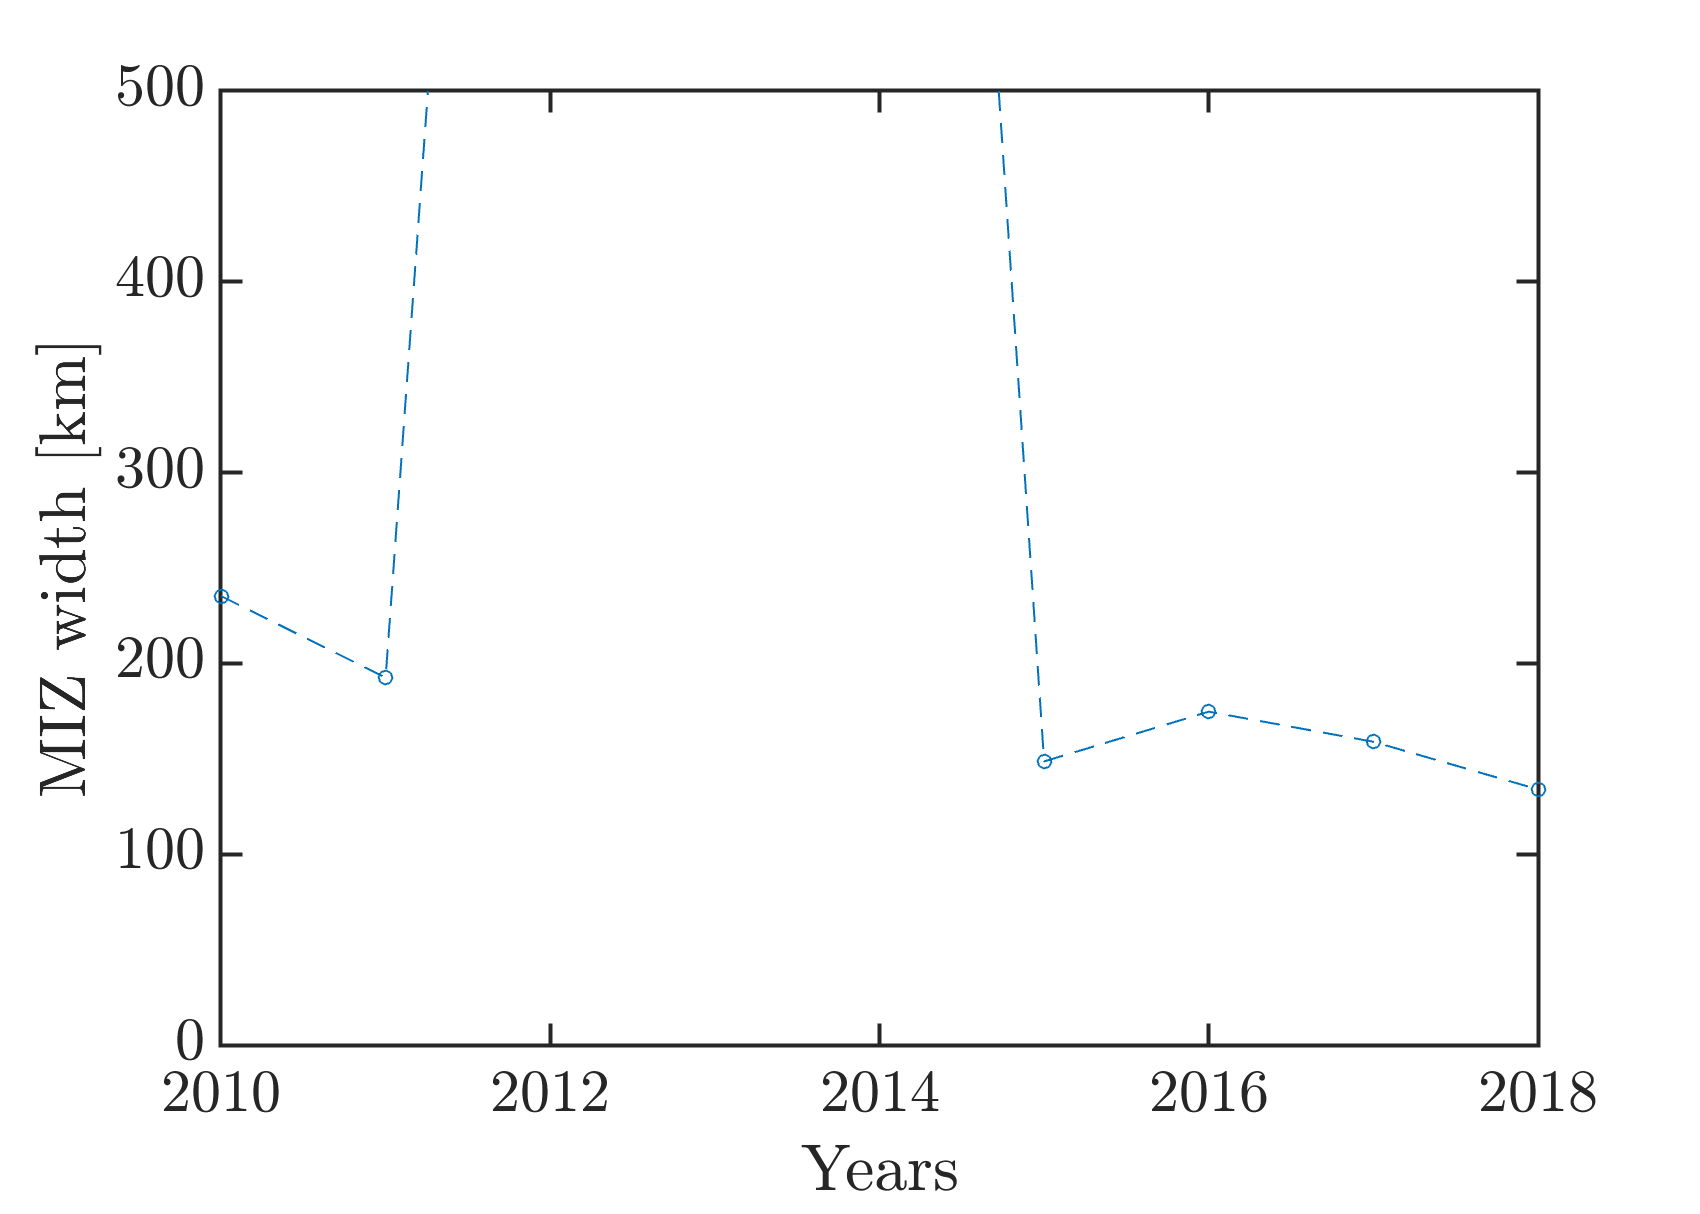


% f = figure;
% plot(1:12,MIZ_width_year,'--o','MarkerSize',7)
% ylabel('MIZ width [km]')
% xticks(1:12)
% xticklabels({'J','F','M','A','M','J','J','A','S','O','N','D'})
% xlabel('Months of 2017')
% ylim([0,800])
% exportgraphics(f,'MIZwidth.pdf','ContentType','vector')

f = figure;
plot(2010:2018,MIZ_width_year,'--o','MarkerSize',7)
ylim([0,500])
ylabel('MIZ width [km]')
%xticks(1:12)
%xticklabels({'J','F','M','A','M','J','J','A','S','O','N','D'})
xlabel('Years')
exportgraphics(f,'MIZwidthyear.pdf','ContentType','vector')

## Functions

function [X_total, idx] = read_data_vec(filenames,sector,var_list)
    [len,~] = size(filenames);
    if len == 1
        filename = filenames;
    else
        filename = filenames(1,:);
    end
    
    SIC_threshold = 0.01;
    [aice, sector_mask] = data_format_sector(filename,"aice",sector);
    [lat,lon,~,ulat,ulon] = grid_read('om2');
    lat_vec = reshape(lat(sector_mask),numel(lat(sector_mask)),1);
    lon_vec = reshape(lon(sector_mask),numel(lon(sector_mask)),1);

    NFSD = ncread(filename,"NFSD");
    NCAT = ncread(filename,"NCAT");
    [floe_binwidth, floe_rad_l, floe_rad_h, floe_area_binwidth] = cice_parameters(NFSD);
    
    X_total = [];
    for j = 1:len
        filename = filenames(j,:);
        [aice, sector_mask] = data_format_sector(filename,"aice",sector);
        ice_mask = aice > SIC_threshold;
        X_temp = [];
        for i = 1:numel(var_list)
            if var_list{i} == "pancake"
                temp = data_format_sector(filename,"afsdn",sector);
                [len, wid] = size(aice);
                for ii = 1:len
                    for jj = 1:wid
                        if aice(ii,jj) > SIC_threshold
                            temp2(ii,jj) =  temp(ii,jj,1,1)./aice(ii,jj).*floe_binwidth(1).*100;
                        else
                            temp2(ii,jj) =  NaN;
                        end
                    end
                end
                %idx = isnan(temp2);
                %temp2(idx) = 0;
                temp_vec = reshape(temp2(sector_mask),numel(temp2(sector_mask)),1);
                X_temp = [X_temp, temp_vec];
            elseif var_list{i} == "full_fsd"
                temp = data_format_sector(filename,"afsd",sector);
                [len, wid] = size(aice);
                for kk = 1:length(NFSD)
                    for ii = 1:len
                        for jj = 1:wid
                            if aice(ii,jj) > SIC_threshold
                                temp2(ii,jj) =  temp(ii,jj,kk)./aice(ii,jj).*floe_binwidth(kk).*100;
                            else
                                temp2(ii,jj) =  NaN;
                            end
                        end
                    end
                %idx = isnan(temp2);
                %temp2(idx) = 0;
                temp_vec = reshape(temp2(sector_mask),numel(temp2(sector_mask)),1);
                X_temp = [X_temp, temp_vec];
                end
            elseif var_list{i} == "full_fstd"
                temp = data_format_sector(filename,"afsdn",sector);
                [len, wid] = size(aice);
                for nc = 1:length(NCAT)
                for kk = 1:length(NFSD)
                    for ii = 1:len
                        for jj = 1:wid
                            if aice(ii,jj) > SIC_threshold
                                temp2(ii,jj) =  temp(ii,jj,kk,nc)./aice(ii,jj).*floe_binwidth(kk).*100;
                            else
                                temp2(ii,jj) =  NaN;
                            end
                        end
                    end
                %idx = isnan(temp2);
                %temp2(idx) = 0;
                temp_vec = reshape(temp2(sector_mask),numel(temp2(sector_mask)),1);
                X_temp = [X_temp, temp_vec];
                end
                end
            elseif var_list{i} == "thick_pan"
                temp = data_format_sector(filename,"afsdn",sector);
                [len, wid] = size(aice);
                for ii = 1:len
                    for jj = 1:wid
                        if aice(ii,jj) > SIC_threshold
                            for ll = 2:5
                                temp2(ii,jj) =  temp2(ii,jj) + temp(ii,jj,1,ll)./aice(ii,jj).*floe_binwidth(1).*100;
                            end
                        else
                            temp2(ii,jj) =  NaN;
                        end
                    end
                end
                %idx = isnan(temp2);
                %temp2(idx) = 0;
                temp_vec = reshape(temp2(sector_mask),numel(temp2(sector_mask)),1);
                X_temp = [X_temp, temp_vec];
            elseif var_list{i} == "large"
                temp = data_format_sector(filename,"afsdn",sector);
                [len, wid] = size(aice);
                for ii = 1:len
                    for jj = 1:wid
                        if aice(ii,jj) > SIC_threshold
                            temp2(ii,jj) =  temp(ii,jj,numel(NFSD),1)./aice(ii,jj).*floe_binwidth(numel(NFSD)).*100;
                        else
                            temp2(ii,jj) =  NaN;
                        end
                    end
                end
                temp_vec = reshape(temp2(sector_mask),numel(temp2(sector_mask)),1);
                X_temp = [X_temp, temp_vec];

            elseif var_list{i} == "dafsd_newi"
                temp = data_format_sector(filename,"dafsd_newi",sector);
                [len, wid] = size(aice);
                for ii = 1:len
                    for jj = 1:wid
                        if aice(ii,jj) > SIC_threshold
                            temp_fsd(:) = temp(ii,jj,:);
                            temp2(ii,jj) =  sum((temp_fsd./aice(ii,jj)).*NFSD');
                        else
                            temp2(ii,jj) =  NaN;
                        end
                    end
                end
                temp_vec = reshape(temp2(sector_mask),numel(temp2(sector_mask)),1);
                X_temp = [X_temp, temp_vec];
            elseif var_list{i} == "dafsd_weld"
                temp = data_format_sector(filename,"dafsd_weld",sector);
                [len, wid] = size(aice);
                for ii = 1:len
                    for jj = 1:wid
                        if aice(ii,jj) > SIC_threshold
                            temp_fsd(:) = temp(ii,jj,:);
                            temp2(ii,jj) =  sum((temp_fsd./aice(ii,jj)).*NFSD');
                        else
                            temp2(ii,jj) =  NaN;
                        end
                    end
                end
                temp_vec = reshape(temp2(sector_mask),numel(temp2(sector_mask)),1);
                X_temp = [X_temp, temp_vec];
            elseif var_list{i} == "dafsd_wave"
                temp = data_format_sector(filename,"dafsd_wave",sector);
                [len, wid] = size(aice);
                for ii = 1:len
                    for jj = 1:wid
                        if aice(ii,jj) > SIC_threshold
                            temp_fsd(:) = temp(ii,jj,:);
                            temp2(ii,jj) =  sum((temp_fsd./aice(ii,jj)).*NFSD');
                        else
                            temp2(ii,jj) =  NaN;
                        end
                    end
                end
                temp_vec = reshape(temp2(sector_mask),numel(temp2(sector_mask)),1);
                X_temp = [X_temp, temp_vec];
            elseif var_list{i} == "dafsd_latm"
                temp = data_format_sector(filename,"dafsd_latm",sector);
                [len, wid] = size(aice);
                for ii = 1:len
                    for jj = 1:wid
                        if aice(ii,jj) > SIC_threshold
                            temp_fsd(:) = temp(ii,jj,:);
                            temp2(ii,jj) =  sum((temp_fsd./aice(ii,jj)).*NFSD');
                        else
                            temp2(ii,jj) =  NaN;
                        end
                    end
                end
                temp_vec = reshape(temp2(sector_mask),numel(temp2(sector_mask)),1);
                X_temp = [X_temp, temp_vec];
             elseif var_list{i} == "dafsd_latg"
                temp = data_format_sector(filename,"dafsd_latg",sector);
                [len, wid] = size(aice);
                for ii = 1:len
                    for jj = 1:wid
                        if aice(ii,jj) > SIC_threshold
                            temp_fsd(:) = temp(ii,jj,:);
                            temp2(ii,jj) =  sum((temp_fsd./aice(ii,jj)).*NFSD');
                        else
                            temp2(ii,jj) =  NaN;
                        end
                    end
                end
                temp_vec = reshape(temp2(sector_mask),numel(temp2(sector_mask)),1);
                X_temp = [X_temp, temp_vec];
            elseif var_list{i} == "strair"
                tempx = data_format_sector(filename,"strairx",sector);
                tempy = data_format_sector(filename,"strairy",sector);
                tempx_vec = reshape(tempx(sector_mask),numel(tempx(sector_mask)),1);
                tempy_vec = reshape(tempy(sector_mask),numel(tempy(sector_mask)),1);
                temp_vec = sqrt(tempx_vec.^2 + tempy_vec.^2);
                X_temp = [X_temp, temp_vec];
            elseif var_list{i} == "strocn"
                tempx = data_format_sector(filename,"strocnx",sector);
                tempy = data_format_sector(filename,"strocny",sector);
                tempx_vec = reshape(tempx(sector_mask),numel(tempx(sector_mask)),1);
                tempy_vec = reshape(tempy(sector_mask),numel(tempy(sector_mask)),1);
                temp_vec = sqrt(tempx_vec.^2 + tempy_vec.^2);
                X_temp = [X_temp, temp_vec];
            elseif var_list{i} == "strint"
                tempx = data_format_sector(filename,"strintx",sector);
                tempy = data_format_sector(filename,"strinty",sector);
                tempx_vec = reshape(tempx(sector_mask),numel(tempx(sector_mask)),1);
                tempy_vec = reshape(tempy(sector_mask),numel(tempy(sector_mask)),1);
                temp_vec = sqrt(tempx_vec.^2 + tempy_vec.^2);
                X_temp = [X_temp, temp_vec];
            elseif var_list{i} == "strcor"
                tempx = data_format_sector(filename,"strcorx",sector);
                tempy = data_format_sector(filename,"strcory",sector);
                tempx_vec = reshape(tempx(sector_mask),numel(tempx(sector_mask)),1);
                tempy_vec = reshape(tempy(sector_mask),numel(tempy(sector_mask)),1);
                temp_vec = sqrt(tempx_vec.^2 + tempy_vec.^2);
                X_temp = [X_temp, temp_vec];
            elseif var_list{i} == "vel"
                tempx = data_format_sector(filename,"uvel",sector);
                tempy = data_format_sector(filename,"vvel",sector);
                tempx_vec = reshape(tempx(sector_mask),numel(tempx(sector_mask)),1);
                tempy_vec = reshape(tempy(sector_mask),numel(tempy(sector_mask)),1);
                temp_vec = sqrt(tempx_vec.^2 + tempy_vec.^2);
                X_temp = [X_temp, temp_vec];  
            elseif var_list{i} == "atmspd"
                tempx = data_format_sector(filename,"uatm",sector);
                tempy = data_format_sector(filename,"vatm",sector);
                tempx_vec = reshape(tempx(sector_mask),numel(tempx(sector_mask)),1);
                tempy_vec = reshape(tempy(sector_mask),numel(tempy(sector_mask)),1);
                temp_vec = sqrt(tempx_vec.^2 + tempy_vec.^2);
                X_temp = [X_temp, temp_vec];  
            else
                temp = data_format_sector(filename,var_list{i},sector);
                temp(~ice_mask) = NaN;
                temp_vec = reshape(temp(sector_mask),numel(temp(sector_mask)),1);
                X_temp = [X_temp, temp_vec];
            end
        end 
        X_temp = [X_temp, lat_vec, lon_vec];
        [idx(j),~] = size(X_temp);
        X_total(:,:,j) = X_temp; %[X_total; X_temp];
    end
   
end


function var_out = variable_dict(var_in)
    for i = 1:numel(var_in)
        if var_in{i} == "aice"
            var_out{i} = 'SIC';
        elseif var_in{i} == "hi"
            var_out{i} = 'Ice thickness';
        elseif var_in{i} == "iage"
            var_out{i} = 'Ice age';
        elseif var_in{i} == "fsdrad"
            var_out{i} = 'Floe mean radius';
        elseif var_in{i} == "pancake"
            var_out{i} = 'Pancake ice';
        elseif var_in{i} == "large"
            var_out{i} = 'Sheet ice';
        elseif var_in{i} == "wave_sig_ht"
            var_out{i} = 'Sig. wave height';
        elseif var_in{i} == "frazil"
            var_out{i} = 'Frazil';
        elseif var_in{i} == "frzmlt"
            var_out{i} = 'Freeze/melt pot.';
        elseif var_in{i} == "congel"
            var_out{i} = 'Congelation rate';
        elseif var_in{i} == "ice_present"
            var_out{i} = 'Ice present';
        elseif var_in{i} == "peak_period"
            var_out{i} = 'Peak period';
        elseif var_in{i} == "vel"
            var_out{i} = 'Ice speed';
        elseif var_in{i} == "strint"
            var_out{i} = 'Internal stress';
        elseif var_in{i} == "Tair"
            var_out{i} = 'Air temp.';
        elseif var_in{i} == "dafsd_latg"
            var_out{i} = 'Lat growth';
        elseif var_in{i} == "dafsd_latm"
            var_out{i} = 'Lat melt';
        elseif var_in{i} == "dafsd_newi"
            var_out{i} = 'New ice';
        elseif var_in{i} == "dafsd_weld"
            var_out{i} = 'Welding';
        elseif var_in{i} == "dafsd_wave"
            var_out{i} = 'Wave breakup';
        elseif var_in{i} == "dafsd_wave"
            var_out{i} = 'Wave breakup';
        elseif var_in{i} == "full_fsd"
            for j = 1:12
                var_out{i+j-1} = sprintf('FSD cat. %g',j);
            end
        elseif var_in{i} == "full_fstd"
            count = 1;
           for nc = 1:5
                for j = 1:12
                    var_out{i+count-1} = sprintf('FSTD cat. (%g %g)',j,nc);
                    count = count + 1;
                end
            end
        else
            var_out{i} = var_in{i};
        end
    end
end


function [MIZ_width, class,MIZ] = calculate_miz_width(filename,sector,k_means,miz_def)
    aice = data_format_sector(filename,'aice',sector);
    [lat,lon,~,ulat,ulon] = grid_read('om2');
    ice_mask =  aice > 0.15;
    k_means(~ice_mask) = NaN;
    idx_miz = isnan(k_means(1,:));
    [len,~] = size(aice);
    for i = 1:len
        temp = k_means(i,~idx_miz);
        edge_class(i) = temp(end); % Take the last cell that > 0.15 SIC
    end
    idx = isnan(edge_class);
    class = mode(edge_class(~idx));
    MIZ = k_means == miz_def;%class;  
    clear MIZ_width
    
    for i = 1:len
        ulat_vec_temp = ulat(i,:);
        ulon_vec_temp = ulon(i,:);
        MIZ_vec_temp = MIZ(i,:);
        if sum(MIZ_vec_temp) == 0
            MIZ_width(i,1:2) = 0;
        else
            %south_point = find(MIZ_vec_temp, 1, 'first');
            %north_point = find(MIZ_vec_temp, 1, 'last');
            f = find(diff([0,MIZ_vec_temp,0]==1));
            p = f(1:2:end-1);  % Start indices
            y = f(2:2:end)-p;  % Consecutive ones counts
            max_y = find(y == max(y));
            p = p(max_y);
            y = y(max_y);
            south_point = p;
            north_point = p+y;
            temp = pathdist([ulat_vec_temp(south_point-1),ulat_vec_temp(north_point)],[ulon_vec_temp(south_point),ulon_vec_temp(north_point)],'km');
            MIZ_width(i,1:2) = temp(1:2);
        end
    end
    MIZ_width = MIZ_width(:,2);
%     for i = 1:len
%         ulat_vec_temp = lat(i,:);
%         ulon_vec_temp = lon(i,:);
%         MIZ_vec_temp = MIZ_zone(i,:);
%         if sum(MIZ_vec_temp) == 0
%             MIZ_width(i,1:2) = 0;
%         else
%             %south_point = find(MIZ_vec_temp, 1, 'first');
%             %north_point = find(MIZ_vec_temp, 1, 'last');
%             f = find(diff([0,MIZ_vec_temp,0]==1));
%             p = f(1:2:end-1);  % Start indices
%             y = f(2:2:end)-p;  % Consecutive ones counts
%             max_y = find(y == max(y));
%             p = p(max_y);
%             y = y(max_y);
%             south_point = p;
%             north_point = p+y;
%             %temp = pathdist([ulat_vec_temp(south_point-1),ulat_vec_temp(north_point)],[ulon_vec_temp(south_point),ulon_vec_temp(north_point)],'km');
%             MIZ_width(i,1:2) = pathdist([ulat_vec_temp(south_point-1),ulat_vec_temp(north_point)],[ulon_vec_temp(south_point),ulon_vec_temp(north_point)],'km');
%         end
%         clear temp
%     end
%     MIZ_width = MIZ_width(:,2);
end